데이타 읽어 들이기.

%['C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']


clear;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

데이타중 첫번째 batch에서 하나를 선택해서 데이타 확인

%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(2); % src has invaild item on index 1
dest = trainData2(9); % dest has vaild item on index 1

특정데이타는 다른 batch에 나눠져 있는 경우가 있어서 이를 합쳐야 한다.

merge = merge_struct(trainData(2),trainData2(9));

% verify
src.cycle_life

ans = 1179

dest.cycle_life

ans = 982

src.cycle_life + dest.cycle_life - 1

ans = 2160

merge.cycle_life

ans = 2160

length(src.summary.QDischarge)

ans = 1178

length(dest.summary.QDischarge)

ans = 981

length(merge.summary.QDischarge)

ans = 2159

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0753

src.summary.QDischarge(end-1)

ans = 1.0386

src.summary.QDischarge(end)

ans = 1.0382

%%%%
dest.summary.QDischarge(1)

ans = 1.0245

dest.summary.QDischarge(2)

ans = 1.0265

dest.summary.QDischarge(end-1)

ans = 0.8802

dest.summary.QDischarge(end)

ans = 0.8800

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0753

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0386

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0382

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0245

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0265

merge.summary.QDischarge(end-1)

ans = 0.8802

merge.summary.QDischarge(end)

ans = 0.8800

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

///////////

# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']

new_index = 1;
BAT = zeros();
BAT = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));


skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,merge);
            new_index = new_index + 1;
            batNum;      
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end




batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            BAT(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

ryan_gen_data2_desc = 'ryan_gen_data2';
save('ryan_gen_data2.mat','ryan_gen_data2_desc');
save('ryan_gen_data2.mat','BAT' ,'-append')

load ryan_gen_data2.mat

length(BAT)

ans = 124

size(BAT)

ans =      1   124


[BAT.key]

ans = 1×124 string array
    "b1c1"    "b1c2"    "b1c3"    "b1c4"    "b1c5"    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b

{[BAT.key]}

ans = 1×1 cell array
    {["b1c1"    "b1c2"    "b1c3"    "b1c4"    "b1c5"    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c

contains([BAT.key],'b1','IgnoreCase',true)

ans = 1×124 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0


contains([BAT.key],'b2','IgnoreCase',true)

ans = 1×124 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1


contains([BAT.key],'b3','IgnoreCase',true)

ans = 1×124 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


idx1 = find(contains([BAT.key],'b1','IgnoreCase',true))

idx1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41


idx2 = find(contains([BAT.key],'b2','IgnoreCase',true))

idx2 =     42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84


idx3 = find(contains([BAT.key],'b3','IgnoreCase',true))

idx3 =     85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124


idx12 = [idx1 idx2]

idx12 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx13 = [idx1 idx3]

idx13 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    85    86    87    88    89    90    91    92    93


idex23 = [idx2 idx3]

idex23 =     42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91


idxAll = (1:length(BAT))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx123 = [idx1 idx2 idx3]

idx123 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


key1 = [BAT(idx1).key]'

key1 = 41×1 string array
    "b1c1"
    "b1c2"
    "b1c3"
    "b1c4"
    "b1c5"
    "b1c6"
    "b1c7"
    "b1c8"
    "b1c10"
    "b1c12"
    "b1c15"
    "b1c16"
    "b1c17"
    "b1c18"
    "b1c19"
    "b1c20"
    "b1c21"
    "b1c22"
    "b1c24"
    "b1c25"
    "b1c26"
    "b1c27"
    "b1c28"
    "b1c29"
    "b1c30"
    "b1c31"
    "b1c32"
    "b1c33"
    "b1c34"
    "b1c35"


key2 = [BAT(idx2).key]'

key2 = 43×1 string array
    "b2c1"
    "b2c2"
    "b2c3"
    "b2c4"
    "b2c5"
    "b2c6"
    "b2c7"
    "b2c11"
    "b2c12"
    "b2c13"
    "b2c14"
    "b2c15"
    "b2c18"
    "b2c19"
    "b2c20"
    "b2c21"
    "b2c22"
    "b2c23"
    "b2c24"
    "b2c25"
    "b2c26"
    "b2c27"
    "b2c28"
    "b2c29"
    "b2c30"
    "b2c31"
    "b2c32"
    "b2c33"
    "b2c34"
    "b2c35"


key3 = [BAT(idx3).key]'

key3 = 40×1 string array
    "b3c1"
    "b3c2"
    "b3c4"
    "b3c5"
    "b3c6"
    "b3c7"
    "b3c8"
    "b3c9"
    "b3c10"
    "b3c11"
    "b3c12"
    "b3c13"
    "b3c14"
    "b3c15"
    "b3c16"
    "b3c17"
    "b3c18"
    "b3c19"
    "b3c20"
    "b3c21"
    "b3c22"
    "b3c23"
    "b3c25"
    "b3c26"
    "b3c27"
    "b3c28"
    "b3c29"
    "b3c30"
    "b3c31"
    "b3c32"


전체 데이타 셋의 discahrge Q 를 smooth해서 표시

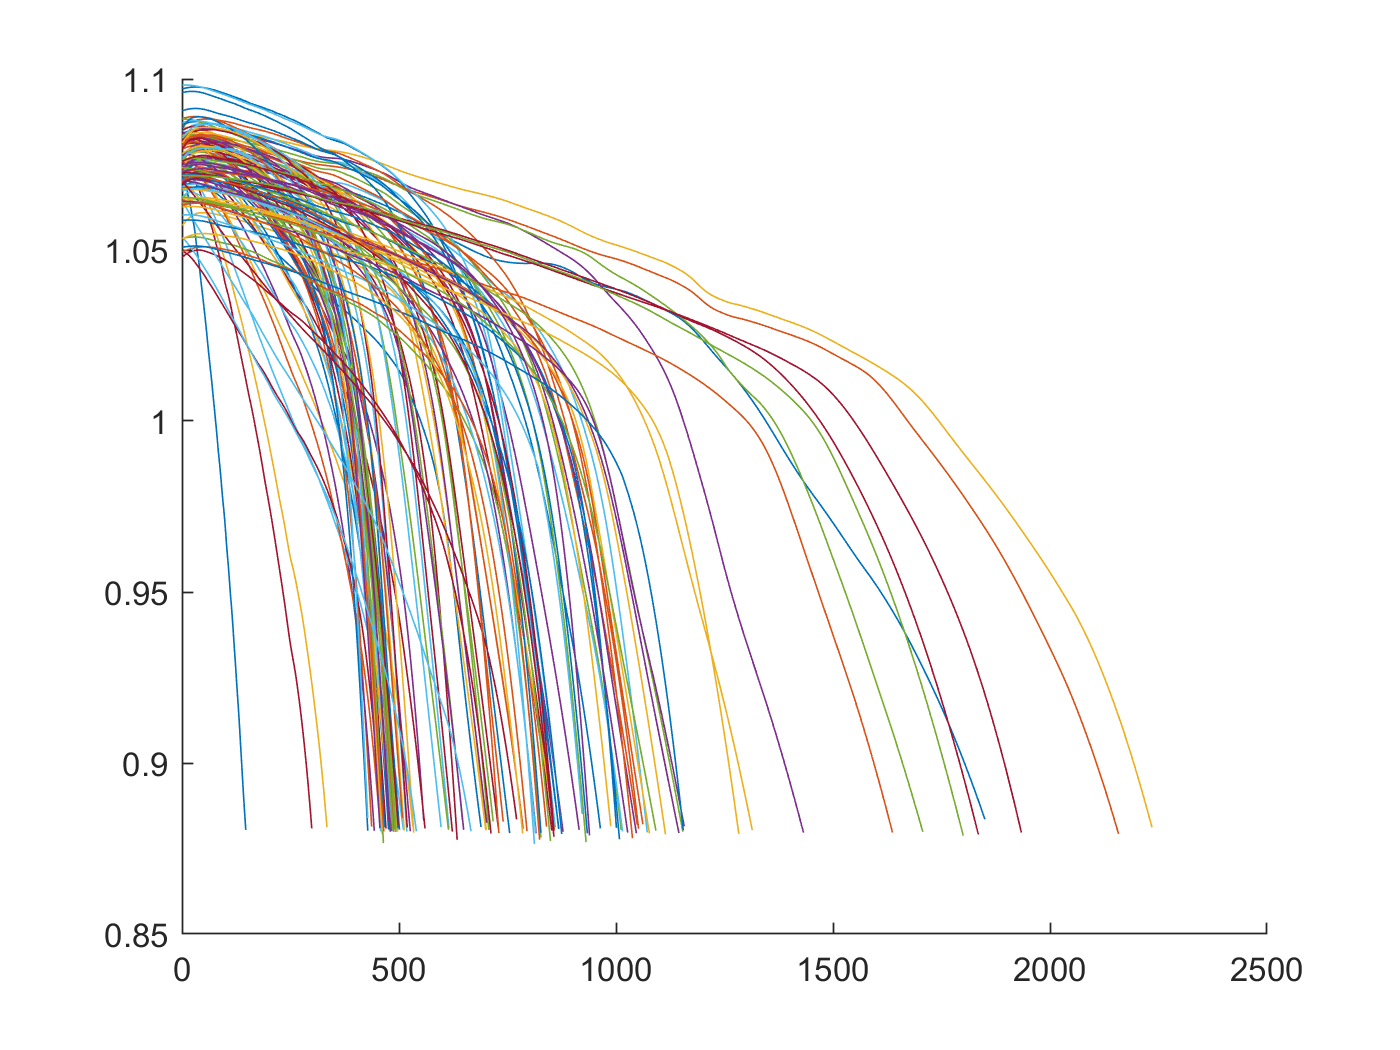

% here
figure
hold on
for i=1:length(idxAll)
    plot(BAT(idxAll(i)).QDischargeSmooth)
end
hold off

batch 1,2 의 discharge Q 만 표시 = training set으로 사용할 예정

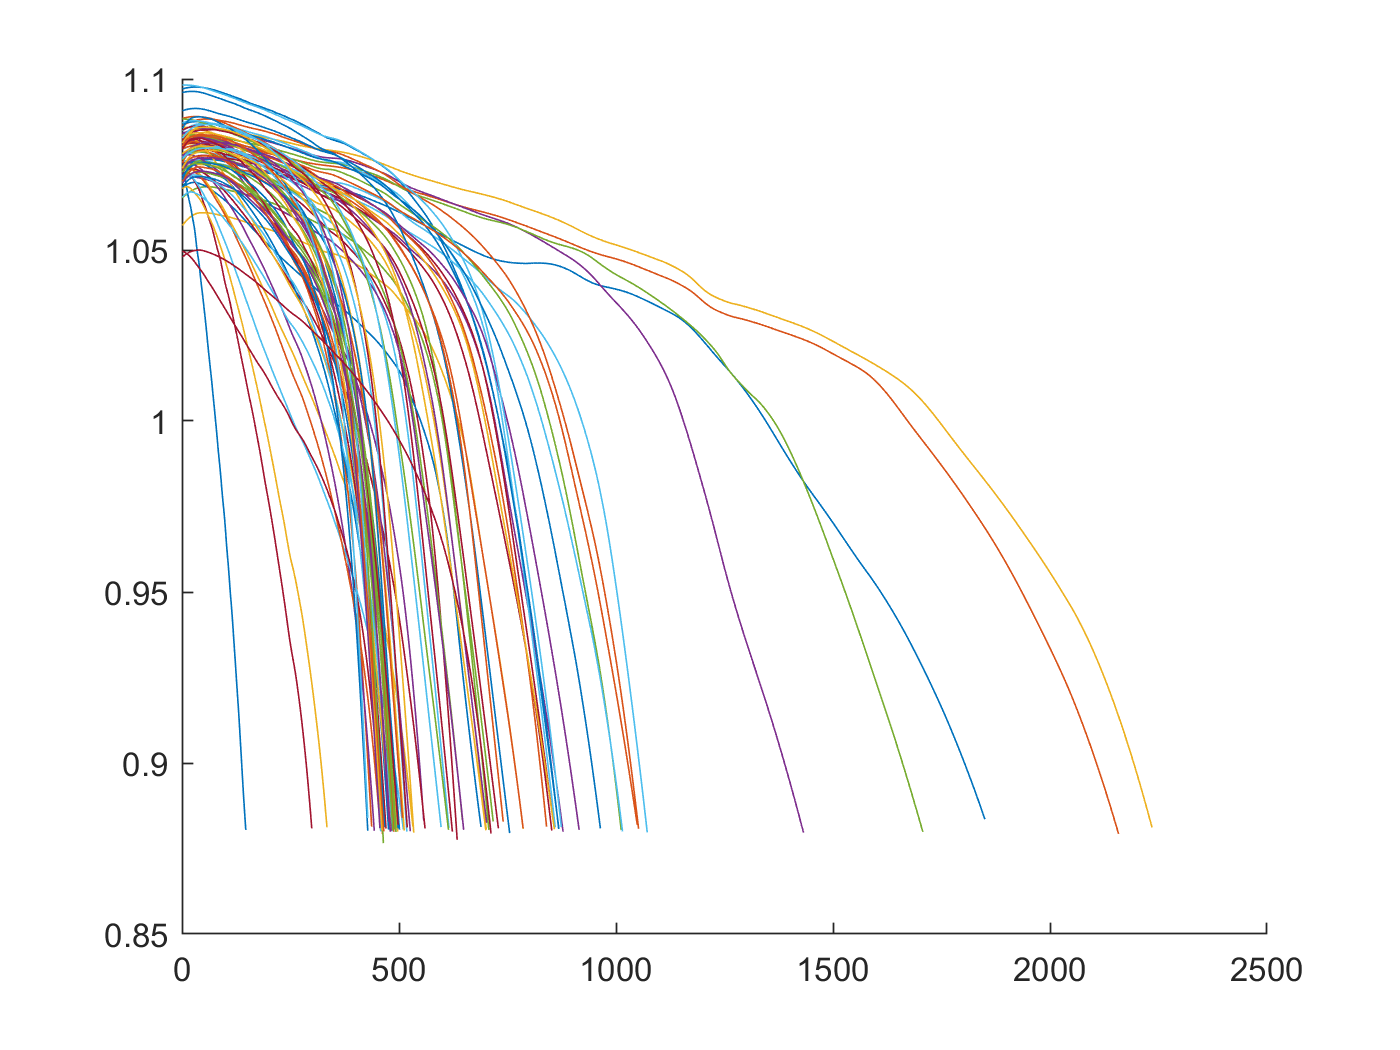

figure
hold on
for i=1:length(idx12)
    plot(BAT(idx12(i)).QDischargeSmooth)
end
hold off

batch 3 의 discharge Q 만 표시 = test set으로 사용할 예정

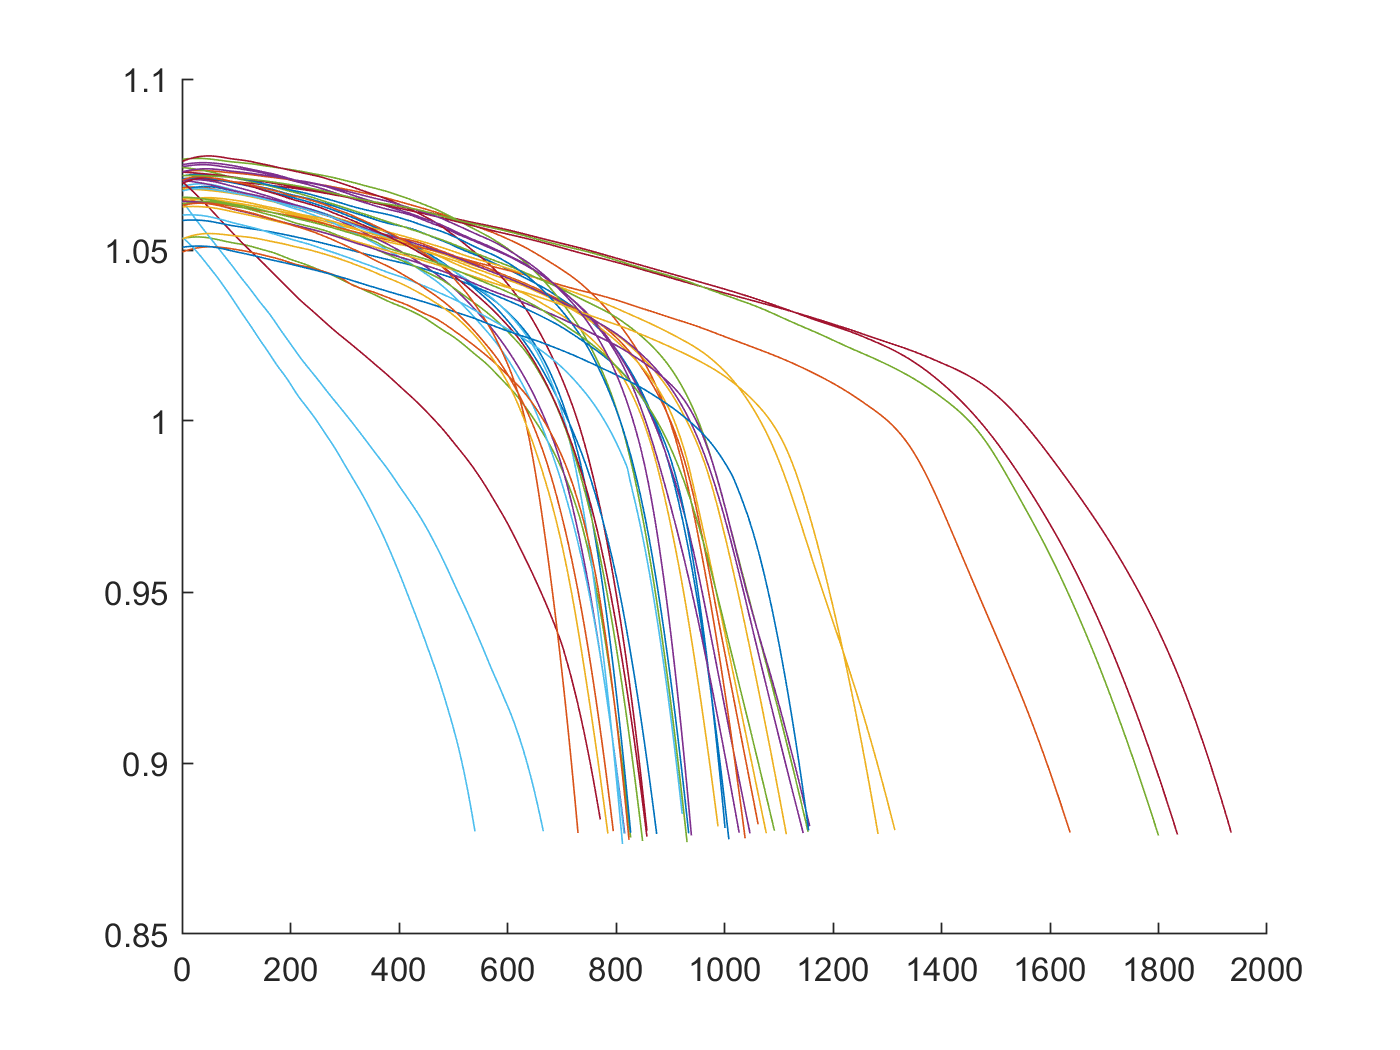

figure
hold on
for i=1:length(idx3)
    plot(BAT(idx3(i)).QDischargeSmooth)
end
hold off

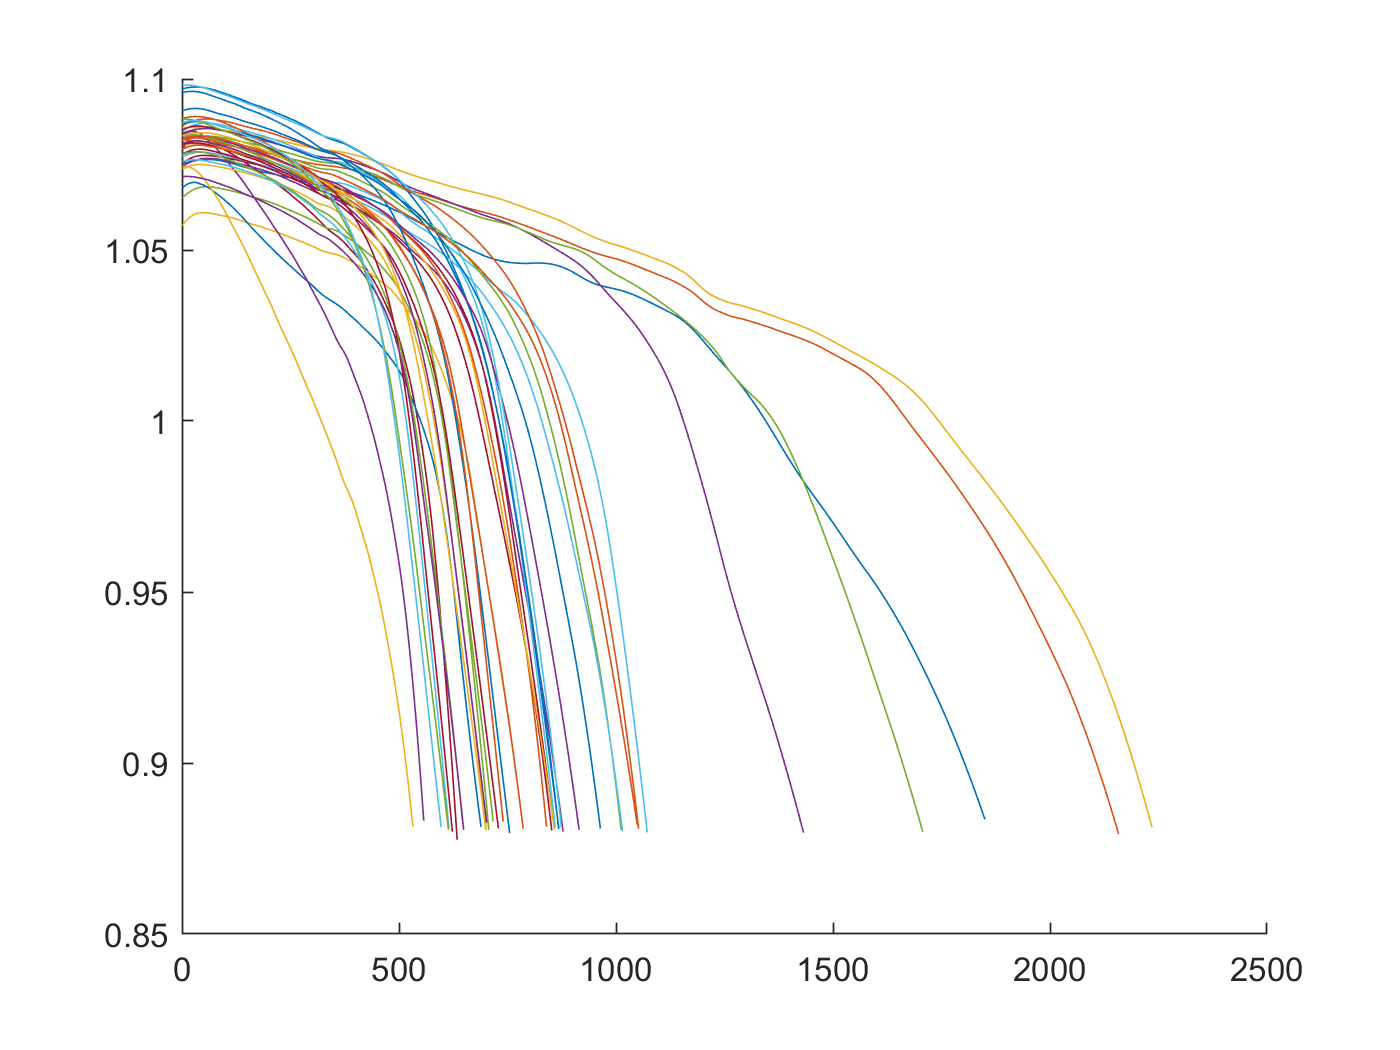


figure
hold on
for i=1:length(idx1)
    plot(BAT(idx1(i)).QDischargeSmooth)
end
hold off

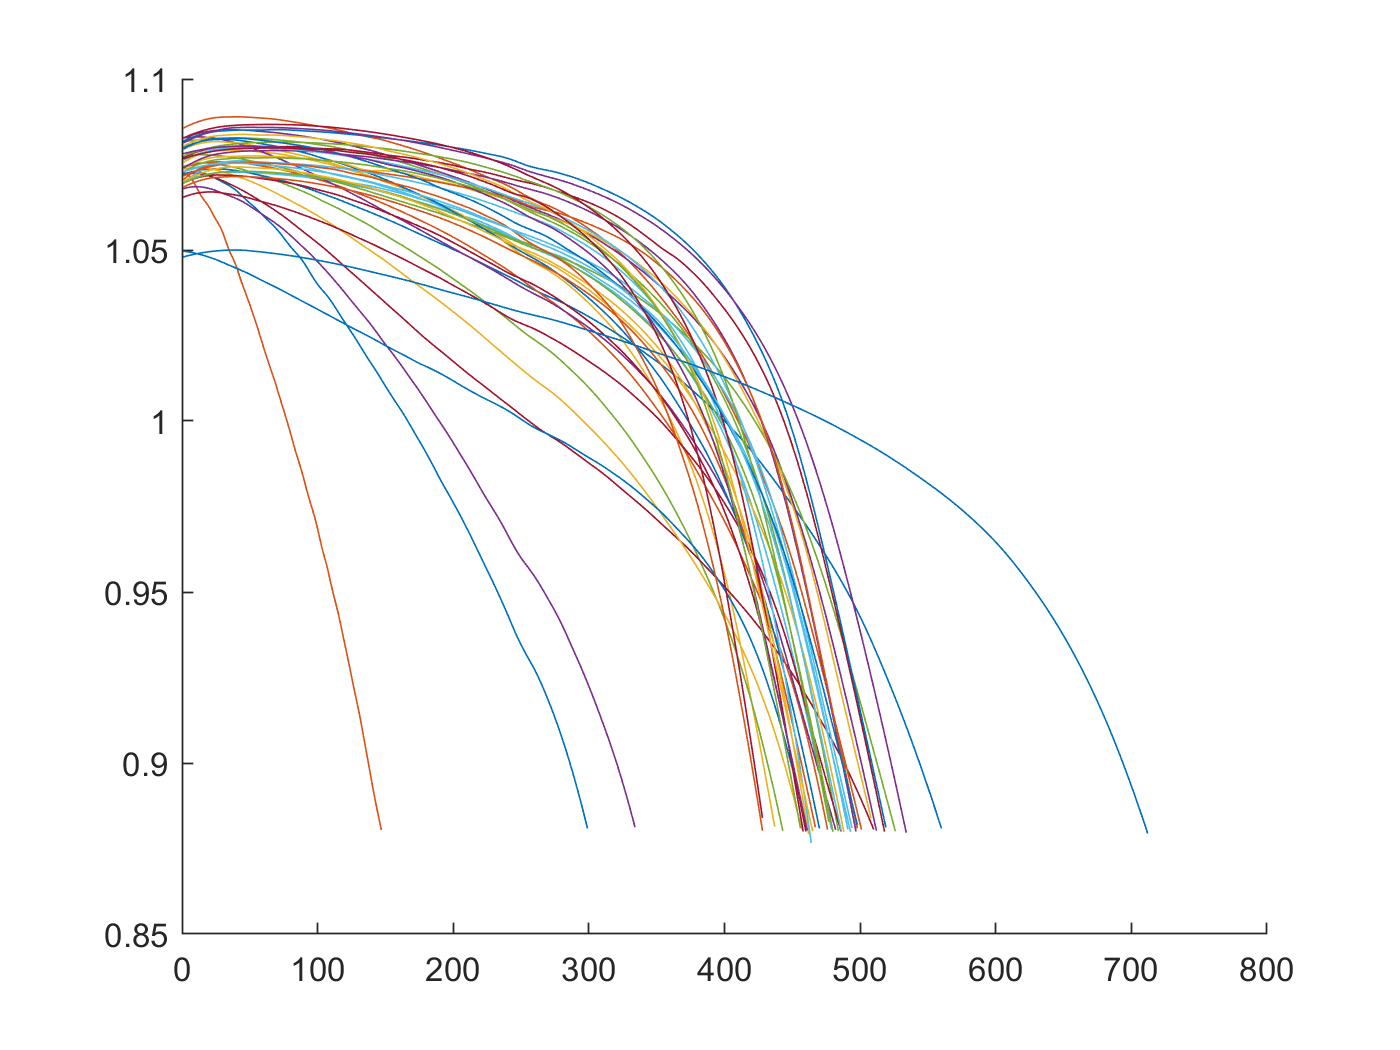


figure
hold on
for i=1:length(idx2)
    plot(BAT(idx2(i)).QDischargeSmooth)
end
hold off


figure
hold on
for i=1:length(idx3)
    plot(BAT(idx3(i)).QDischargeSmooth)
end
hold off

test dataset (batch1,2) 에서 값을 정규화하기

%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 잘 동작하지 않음
%idx = idx13 ; % training set - 잘 동작하지 않음
%idx = idx1;
key = [BAT(idx).key]';
s = string([BAT(idx).policy])

s = "3_6C-80PER_3_6C3_6C-80PER_3_6C3_6C-80PER_3_6C4C-80PER_4C4C-80PER_4C4_4C-80PER_4_4C4_8C-80PER_4_8C4_8C-80PER_4_8C5_4C-40PER_3_6C5_4C-50PER_3C5_4C-60PER_3C5_4C-60PER_3C5_4C-60PER_3_6C5_4C-60PER_3_6C5_4C-70PER_3C5_4C-70PER_3C5_4C-80PER_5_4C5_4C-80PER_5_4C6C-30PER_3_6C6C-40PER_3C6C-40PER_3C6C-40PER_3_6C6C-40PER_3_6C6C-50PER_3C6C-50PER_3C6C-50PER_3_6C6C-50PER_3_6C6C-60PER_3C6C-60PER_3C7C-30PER_3_6C7C-30PER_3_6C7C-40PER_3C7C-40PER_3C7C-40PER_3_6C7C-40PER_3_6C8C-15PER_3_6C8C-15PER_3_6C8C-25PER_3_6C8C-25PER_3_6C8C-35PER_3_6C8C-35PER_3_6C1C_4PER_6C2C_10PER_6C2C_2PER_5C2C_7PER_5_5C3_6C_22PER_5_5C3_6C_2PER_4_85C3_6C_30PER_6C3_6C_9PER_5C4C_13PER_5C4C_31PER_54C_40PER_6C4C_4PER_4_85C4_4C_24PER_5C4_4C_47PER_5_5C4_4C_55PER_6C4_4C_8PER_4_85C4_65C_19PER_4_85C4_65C_44PER_5C4_65C_69PER_6C4_8C_80PER_4_8C4_8C_80PER_4_8C4_8C_80PER_4_8C4_9C_27PER_4_75C4_9C_61PER_4_5C4_9C_69PER_4_25C5_2C_10PER_4_75C5_2C_37PER_4_5C5_2C_50PER_4_25C5_2C_58PER_4C5_2C_66PER_3_5C5_2C_71PER_3C5_6C_25PER_4_5C5_6C_38PER_4_25C5_6C_

s1 = string([{BAT(idx).policy}])

s1 = 1×84 string array
    "3_6C-80PER_3_6C"    "3_6C-80PER_3_6C"    "3_6C-80PER_3_6C"    "4C-80PER_4C"    "4C-80PER_4C"    "4_4C-80PER_4_4C"    "4_8C-80PER_4_8C"    "4_8C-80PER_4_8C"    "5_4C-40PER_3_6C"    "5_4C-50PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3_6C"    "5_4C-60PER_3_6C"    "5_4C-70PER_3C"    "5_4C-70PER_3C"    "5_4C-80PER_5_4C"    "5_4C-80PER_5_4C"    "6C-30PER_3_6C"    "6C-40PER_3C"    "6C-40PER_3C"    "6C-40PER_3_6C"    "6C-40PER_3_6C"    "6C-50PER_3C"    "6C-50PER_3C"    "6C-50PER_3_6C"    "6C-50PER_3_6C"    "6C-60PER_3C"    "6C-60PER_3C"    "7C-30PER_3_6C"    "7C-30PER_3_6C"    "7C-40PER_3C"    "7C-40PER_3C"    "7C-40PER_3_6C"    "7C-40PER_3_6C"    "8C-15PER_3_6C"    "8C-15PER_3_6C"    "8C-25PER_3_6C"    "8C-25PER_3_6C"    "8C-35PER_3_6C"    "8C-35PER_3_6C"    "1C_4PER_6C"    "2C_10PER_6C"    "2C_2PER_5C"    "2C_7PER_5_5C"    "3_6C_22PER_5_5C"    "3_6C_2PER_4_85C"    "3_6C_30PER_6C"    "3_6C_9PER_5C"    "4C_13PER_5C"    "4C_31PER_5"    "4C_40PER_6C"

policy = [{BAT(idx).policy}]';
policy_str = string([{BAT(idx).policy}]');
policy_readable = [{BAT(idx).policy_readable}]';
policy_readable_str = string([{BAT(idx).policy_readable}]');
Ic1 = [{BAT(idx).Ic}]';
Ic2 = [BAT(idx).Ic];
Ic3 = reshape(Ic2,100,length(policy));
Ic = Ic3';
cycle = [BAT(idx).cycle_life ]';
x=Ic;
y=cycle;
[ynorm,ymin,yrate,xnorm,xmin,xrate] = minmax_norm_new(y,x);

min(y)

ans = 147

max(y)

ans = 2235


yrate =  max(y) - min(y)

yrate = 2088

ymin = min(y)

ymin = 147

ynorm = (y - ymin) / yrate

ynorm =     0.8156
    0.9631
    1.0000
    0.6154
    0.7471
    0.4430
    0.2332
    0.3453
    0.4334
    0.3060


yback = ynorm * yrate + ymin

yback = 	1.0e+03 *

    1.8500
    2.1580
    2.2350
    1.4320
    1.7070
    1.0720
    0.6340
    0.8680
    1.0520
    0.7860


y

y =         1850
        2158
        2235
        1432
        1707
        1072
         634
         868
        1052
         786


x

x =          0    3.6001    3.6003    3.6000    3.6002    3.5998    3.6002    3.6000    3.6000    3.6001    3.6000    3.6001    3.6001    3.5999    3.6003    3.5996    3.5999    3.5999    3.5998    3.6000    3.6000    3.6002    3.5999    3.5995    3.5998    3.6002    3.5995    3.5997    3.6000    3.6000    3.6000    3.6000    3.5999    3.5997    3.6002    3.6000    3.5998    3.6001    3.6002    3.6001    3.5998    3.6004    3.5998    3.5999    3.6000    3.6000    3.6002    3.5999    3.5993    3.6000
         0    3.5999    3.5998    3.5996    3.5999    3.6002    3.6002    3.6003    3.5997    3.6000    3.5996    3.5999    3.6000    3.5999    3.5999    3.6000    3.5999    3.6002    3.5999    3.6001    3.5994    3.6002    3.6000    3.5994    3.5998    3.6001    3.5999    3.6001    3.6003    3.5999    3.6001    3.6003    3.6000    3.6006    3.6000    3.6004    3.6000    3.5999    3.6002    3.5996    3.6004    3.5995    3.5999    3.6002    3.5999    3.5998    3.6002    3.6000    3.6000    3

min(min(x))

ans = 0

max(max(x))

ans = 8.0067

xrate =  max(max(x)) - min(min(x))

xrate = 8.0067

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.4496    0.4497    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4495    0.4496
         0    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4497    0.4496    0.4497    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4497    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496    0.4496 

xback = xnorm * xrate + xmin

xback =          0    3.6001    3.6003    3.6000    3.6002    3.5998    3.6002    3.6000    3.6000    3.6001    3.6000    3.6001    3.6001    3.5999    3.6003    3.5996    3.5999    3.5999    3.5998    3.6000    3.6000    3.6002    3.5999    3.5995    3.5998    3.6002    3.5995    3.5997    3.6000    3.6000    3.6000    3.6000    3.5999    3.5997    3.6002    3.6000    3.5998    3.6001    3.6002    3.6001    3.5998    3.6004    3.5998    3.5999    3.6000    3.6000    3.6002    3.5999    3.5993    3.6000
         0    3.5999    3.5998    3.5996    3.5999    3.6002    3.6002    3.6003    3.5997    3.6000    3.5996    3.5999    3.6000    3.5999    3.5999    3.6000    3.5999    3.6002    3.5999    3.6001    3.5994    3.6002    3.6000    3.5994    3.5998    3.6001    3.5999    3.6001    3.6003    3.5999    3.6001    3.6003    3.6000    3.6006    3.6000    3.6004    3.6000    3.5999    3.6002    3.5996    3.6004    3.5995    3.5999    3.6002    3.5999    3.5998    3.6002    3.6000    3.6000 

x

x =          0    3.6001    3.6003    3.6000    3.6002    3.5998    3.6002    3.6000    3.6000    3.6001    3.6000    3.6001    3.6001    3.5999    3.6003    3.5996    3.5999    3.5999    3.5998    3.6000    3.6000    3.6002    3.5999    3.5995    3.5998    3.6002    3.5995    3.5997    3.6000    3.6000    3.6000    3.6000    3.5999    3.5997    3.6002    3.6000    3.5998    3.6001    3.6002    3.6001    3.5998    3.6004    3.5998    3.5999    3.6000    3.6000    3.6002    3.5999    3.5993    3.6000
         0    3.5999    3.5998    3.5996    3.5999    3.6002    3.6002    3.6003    3.5997    3.6000    3.5996    3.5999    3.6000    3.5999    3.5999    3.6000    3.5999    3.6002    3.5999    3.6001    3.5994    3.6002    3.6000    3.5994    3.5998    3.6001    3.5999    3.6001    3.6003    3.5999    3.6001    3.6003    3.6000    3.6006    3.6000    3.6004    3.6000    3.5999    3.6002    3.5996    3.6004    3.5995    3.5999    3.6002    3.5999    3.5998    3.6002    3.6000    3.6000    3


%cycle = cycle -1;
%cycle_data = [cycle key policy policy_readable];
cycle_data = [cycle key policy_str policy_readable_str];
cycleTable1 = array2table(cycle_data,...
    'VariableNames',{'cycle','key','policy','policy_readable'})

cycleTable1 = 84×4 table
    cycle       key           policy          policy_readable 
    ______    _______    _________________    ________________

    "1850"    "b1c1"     "3_6C-80PER_3_6C"    "3.6C(80%)-3.6C"
    "2158"    "b1c2"     "3_6C-80PER_3_6C"    "3.6C(80%)-3.6C"
    "2235"    "b1c3"     "3_6C-80PER_3_6C"    "3.6C(80%)-3.6C"
    "1432"    "b1c4"     "4C-80PER_4C"        "4C(80%)-4C"    
    "1707"    "b1c5"     "4C-80PER_4C"        "4C(80%)-4C"    
    "1072"    "b1c6"     "4_4C-80PER_4_4C"    "4.4C(80%)-4.4C"
    "634"     "b1c7"     "4_8C-80PER_4_8C"    "4.8C(80%)-4.8C"
    "868"     "b1c8"     "4_8C-80PER_4_8C"    "4.8C(80%)-4.8C"
    "1052"    "b1c10"    "5_4C-40PER_3_6C"    "5.4C(40%)-3.6C"
    "786"     "b1c12"    "5_4C-50PER_3C"      "5.4C(50%)-3C"  
    "878"     "b1c15"    "5_4C-60PER_3C"      "5.4C(60%)-3C"  
    "717"     "b1c1

cycleTable = table(cycle, key, policy_str, policy_readable_str,Ic)

cycleTable = 84×5 table
    cycle      key         policy_str        policy_readable_str          Ic      
    _____    _______    _________________    ___________________    ______________

    1850     "b1c1"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    2158     "b1c2"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    2235     "b1c3"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    1432     "b1c4"     "4C-80PER_4C"         "4C(80%)-4C"          [1×100 double]
    1707     "b1c5"     "4C-80PER_4C"         "4C(80%)-4C"          [1×100 double]
    1072     "b1c6"     "4_4C-80PER_4_4C"     "4.4C(80%)-4.4C"      [1×100 double]
     634     "b1c7"     "4_8C-80PER_4_8C"     "4.8C(80%)-4.8C"      [1×100 double]
     868     "b1c8"     "4_8C-80PER_4_8C"     "4.8C(80%)-4

cycleTableSort = sortrows(cycleTable,1,'descend')

cycleTableSort = 84×5 table
    cycle      key         policy_str        policy_readable_str          Ic      
    _____    _______    _________________    ___________________    ______________

    2235     "b1c3"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    2158     "b1c2"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    1850     "b1c1"     "3_6C-80PER_3_6C"     "3.6C(80%)-3.6C"      [1×100 double]
    1707     "b1c5"     "4C-80PER_4C"         "4C(80%)-4C"          [1×100 double]
    1432     "b1c4"     "4C-80PER_4C"         "4C(80%)-4C"          [1×100 double]
    1072     "b1c6"     "4_4C-80PER_4_4C"     "4.4C(80%)-4.4C"      [1×100 double]
    1052     "b1c10"    "5_4C-40PER_3_6C"     "5.4C(40%)-3.6C"      [1×100 double]
    1049     "b1c42"    "8C-15PER_3_6C"       "8C(15%)

전류 패턴에 따른 라이프 사이클 예측 ..

선형회귀 - 정규화 필요 없음.

x = 충전전류 - training set ( batch 1,2)

y = cycle count


%%%%%%%%%%%%%
% FNN/CNN/LSTM
mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                    Estimate      SE    tStat    pValue
                   ___________    __    _____    ______

    (Intercept)              0    0      NaN      NaN  
    x1      

coeff = mdl.Coefficients.Estimate

coeff = 	1.0e+05 *

         0
         0
    0.0108
   -0.0103
    0.2282
   -0.2277
    1.0238
    0.3598
   -2.3095
    0.7865


x(1,:)

ans =          0    3.6001    3.6003    3.6000    3.6002    3.5998    3.6002    3.6000    3.6000    3.6001    3.6000    3.6001    3.6001    3.5999    3.6003    3.5996    3.5999    3.5999    3.5998    3.6000    3.6000    3.6002    3.5999    3.5995    3.5998    3.6002    3.5995    3.5997    3.6000    3.6000    3.6000    3.6000    3.5999    3.5997    3.6002    3.6000    3.5998    3.6001    3.6002    3.6001    3.5998    3.6004    3.5998    3.5999    3.6000    3.6000    3.6002    3.5999    3.5993    3.6000


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x*coeff(2:101)+coeff(1)

yhat = 	1.0e+03 *

    1.8500
    2.1580
    2.2350
    1.4320
    1.7070
    1.0720
    0.6340
    0.8680
    1.0520
    0.7860


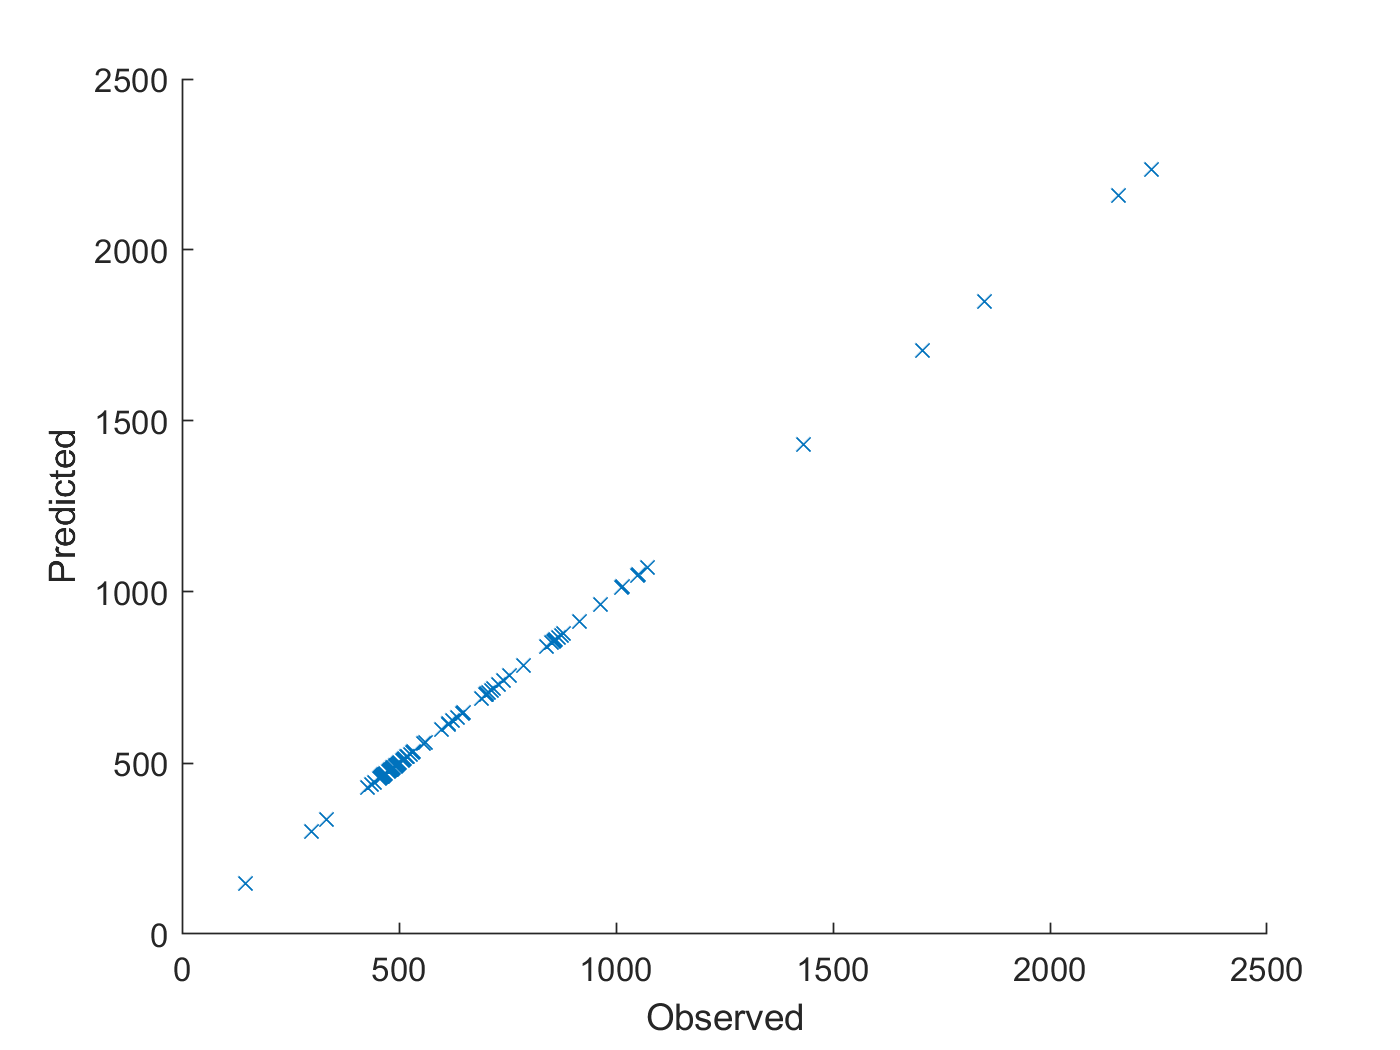

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off

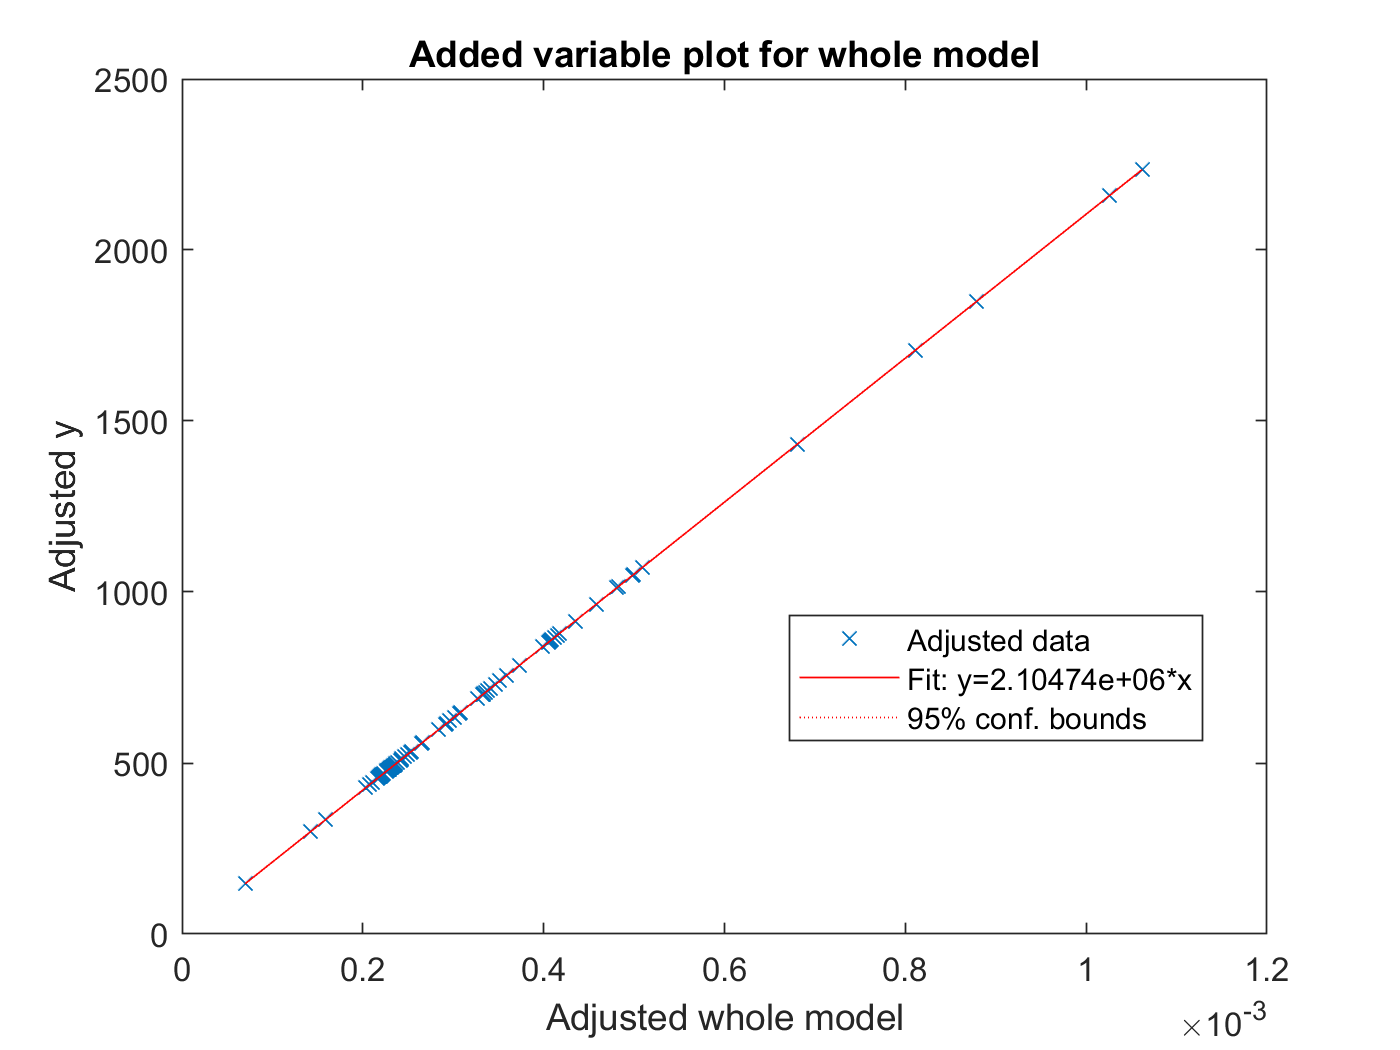


%capHat = Ic(1)

plot(mdl)

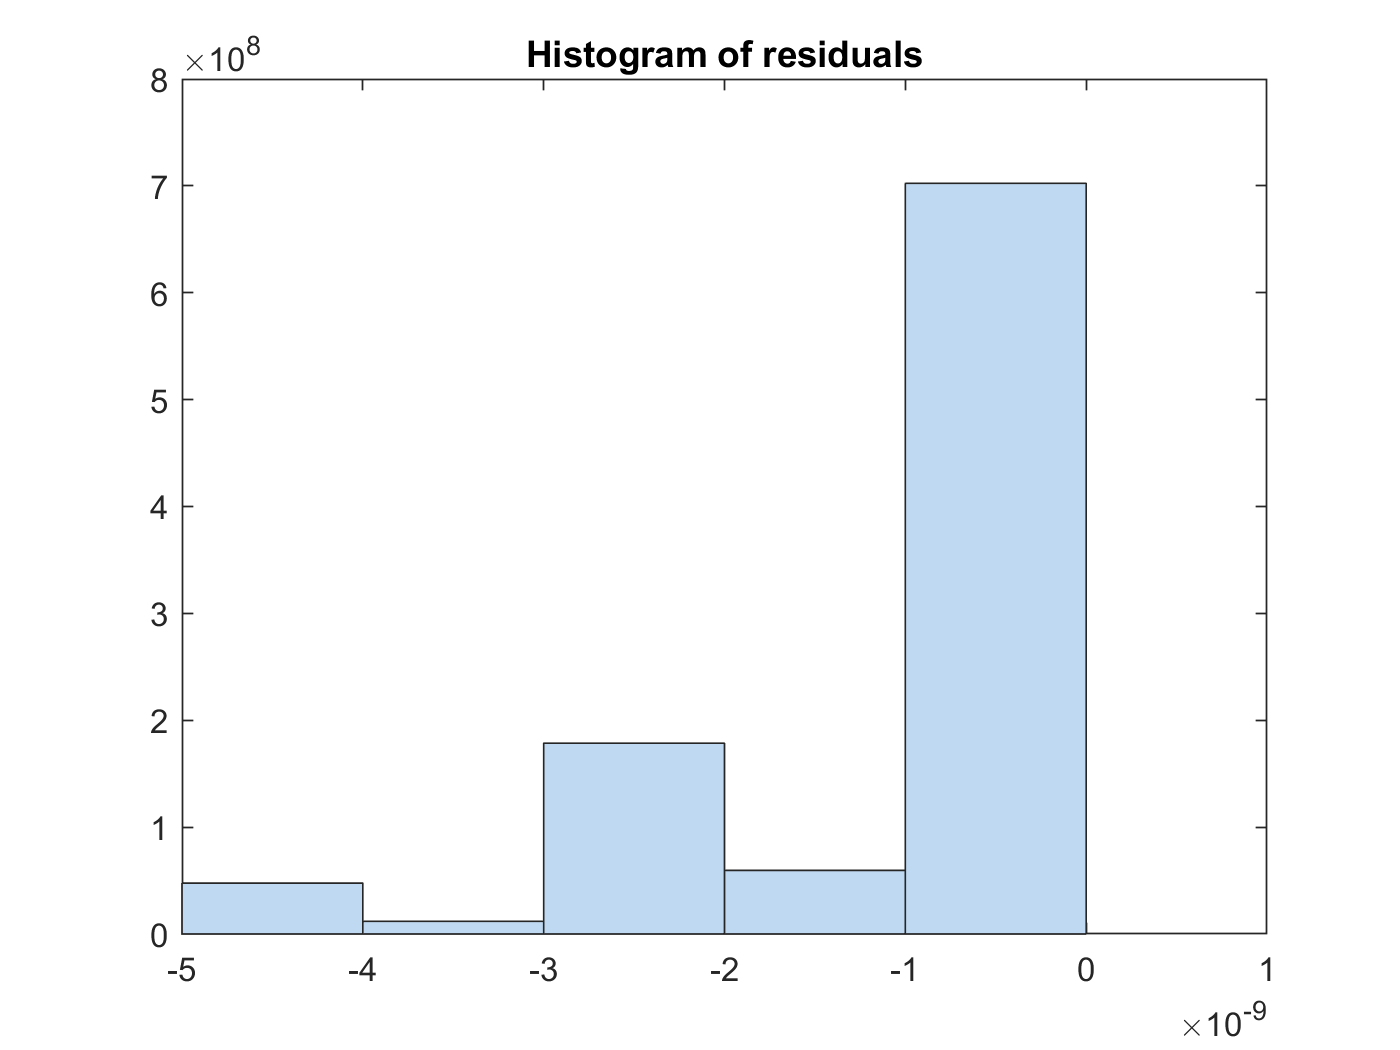

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,Ic)

yfit = 	1.0e+03 *

    1.8500
    2.1580
    2.2350
    1.4320
    1.7070
    1.0720
    0.6340
    0.8680
    1.0520
    0.7860




y= cycle;
MAE = mean(abs(yfit-y))

MAE = 2.5509e-09

adjMAE = MAE/range(y)

adjMAE = 1.2217e-12

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 2088


(y - yhat)    % Errors

ans = 	1.0e+-8 *

   -0.9851
    0.0645
   -0.1698
   -0.1480
   -0.1475
   -0.1812
   -0.2226
   -0.2027
   -0.2155
   -0.2639


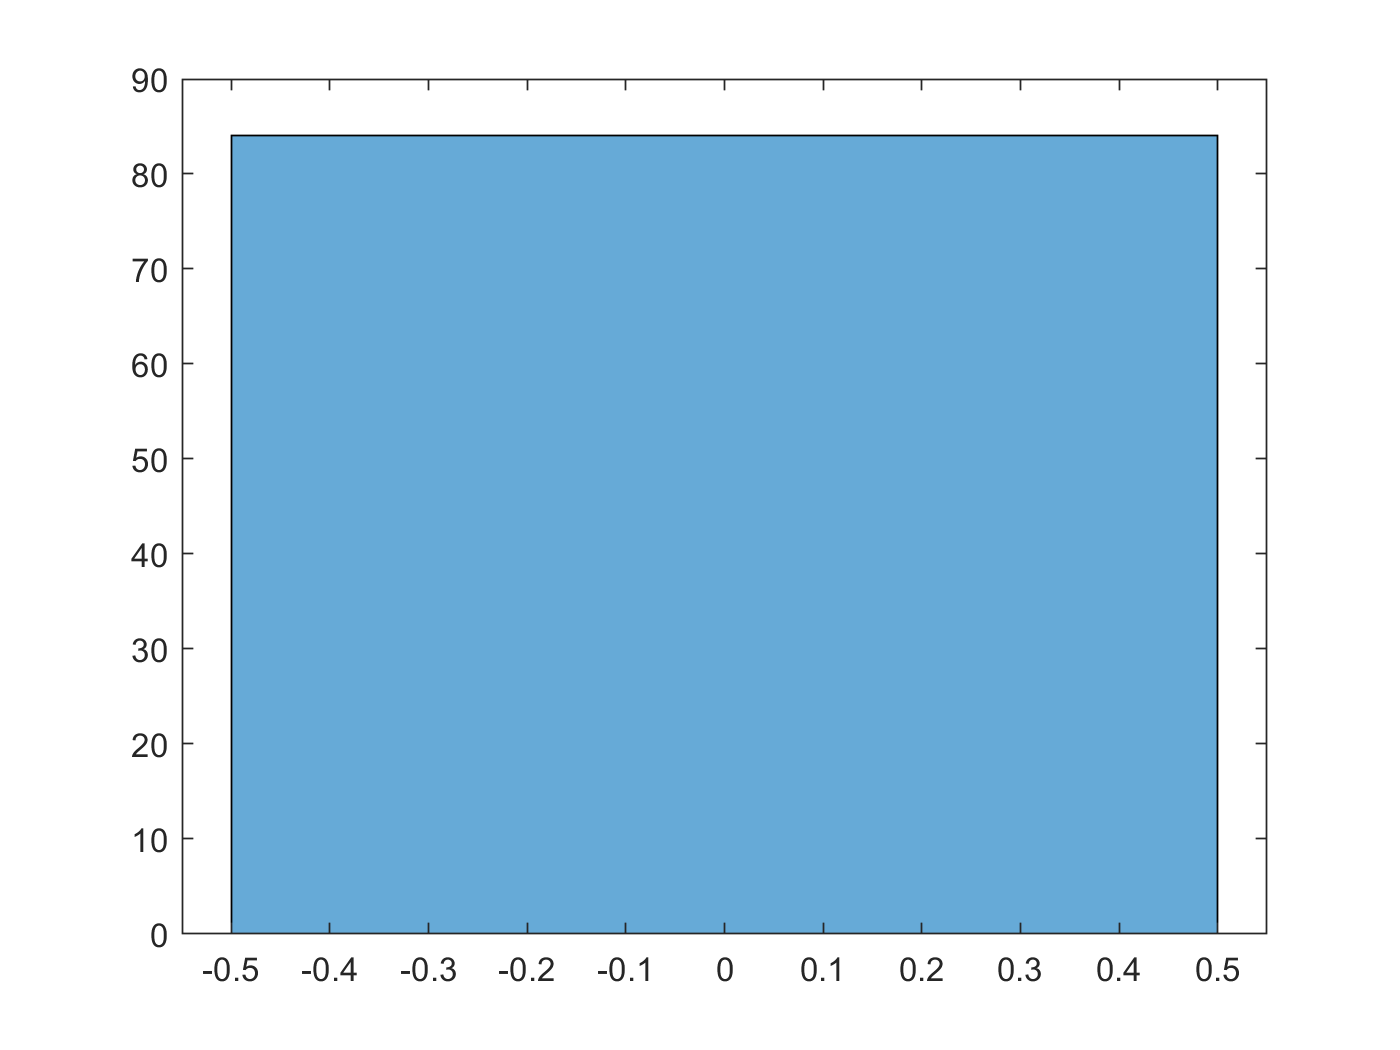

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 2.8092e-09

% 이것으로 입력신호(사용자 패턴)에 대해 예상되는 사이클을 예상할 수 있다.


%{
outlier1 = mdl.Residuals.Raw > 50 ;
outlier2 = mdl.Residuals.Raw < -50 ;
outlier =  outlier1 + outlier2 ;
find(outlier);
mdl = fitlm(x,y,'Exclude',find(outlier))
coeff = mdl.Coefficients.Estimate
x(1,:);
yhat = x*coeff(2:101)+coeff(1)
figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off

%capHat = Ic(1)

plot(mdl)
plotResiduals(mdl)



% yfit = predict(mdl,Ic)
yfit = predict(mdl,Ic)


y= cycle;
MAE = mean(abs(yfit-y))
adjMAE = MAE/range(y)
range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

(y - yhat)    % Errors
(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)
mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error
% 이것으로 입력신호(사용자 패턴)에 대해 예상되는 사이클을 예상할 수 있다.
%}


training set (b1,2)로 b1 예측 - 정확함.

% predict batch1 from model from model
idx = idx1;
Ic_ = [BAT(idx).Ic];
x = (reshape(Ic_,100,[]))';
y = [BAT(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat = 	1.0e+03 *

    1.8500
    2.1580
    2.2350
    1.4320
    1.7070
    1.0720
    0.6340
    0.8680
    1.0520
    0.7860


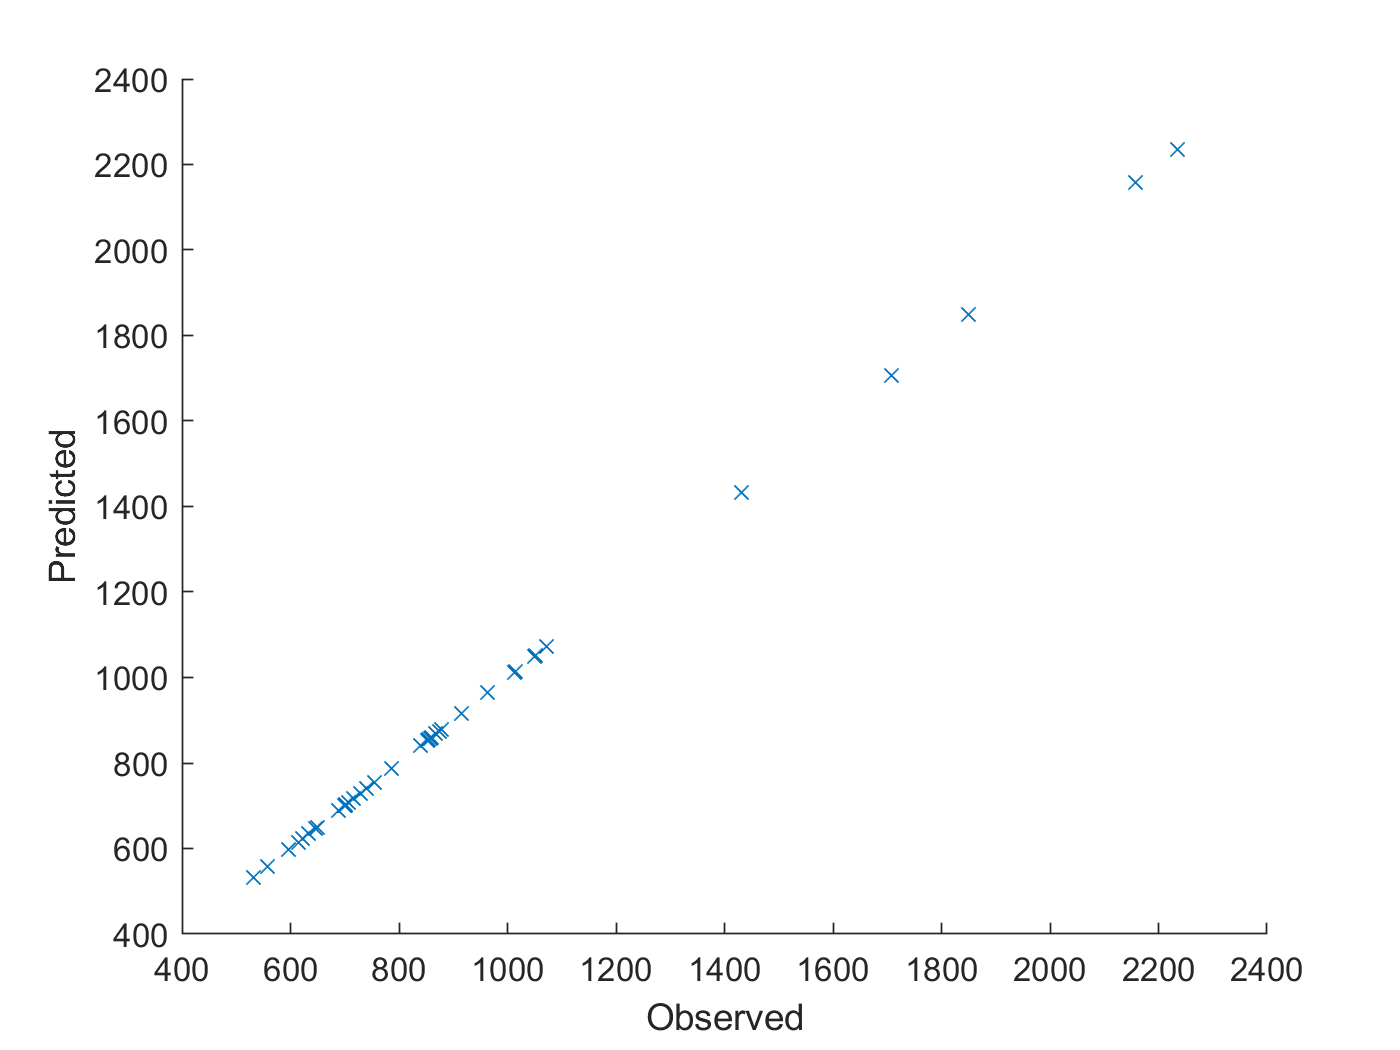

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+-8 *

   -0.9851
    0.0645
   -0.1698
   -0.1480
   -0.1475
   -0.1812
   -0.2226
   -0.2027
   -0.2155
   -0.2639


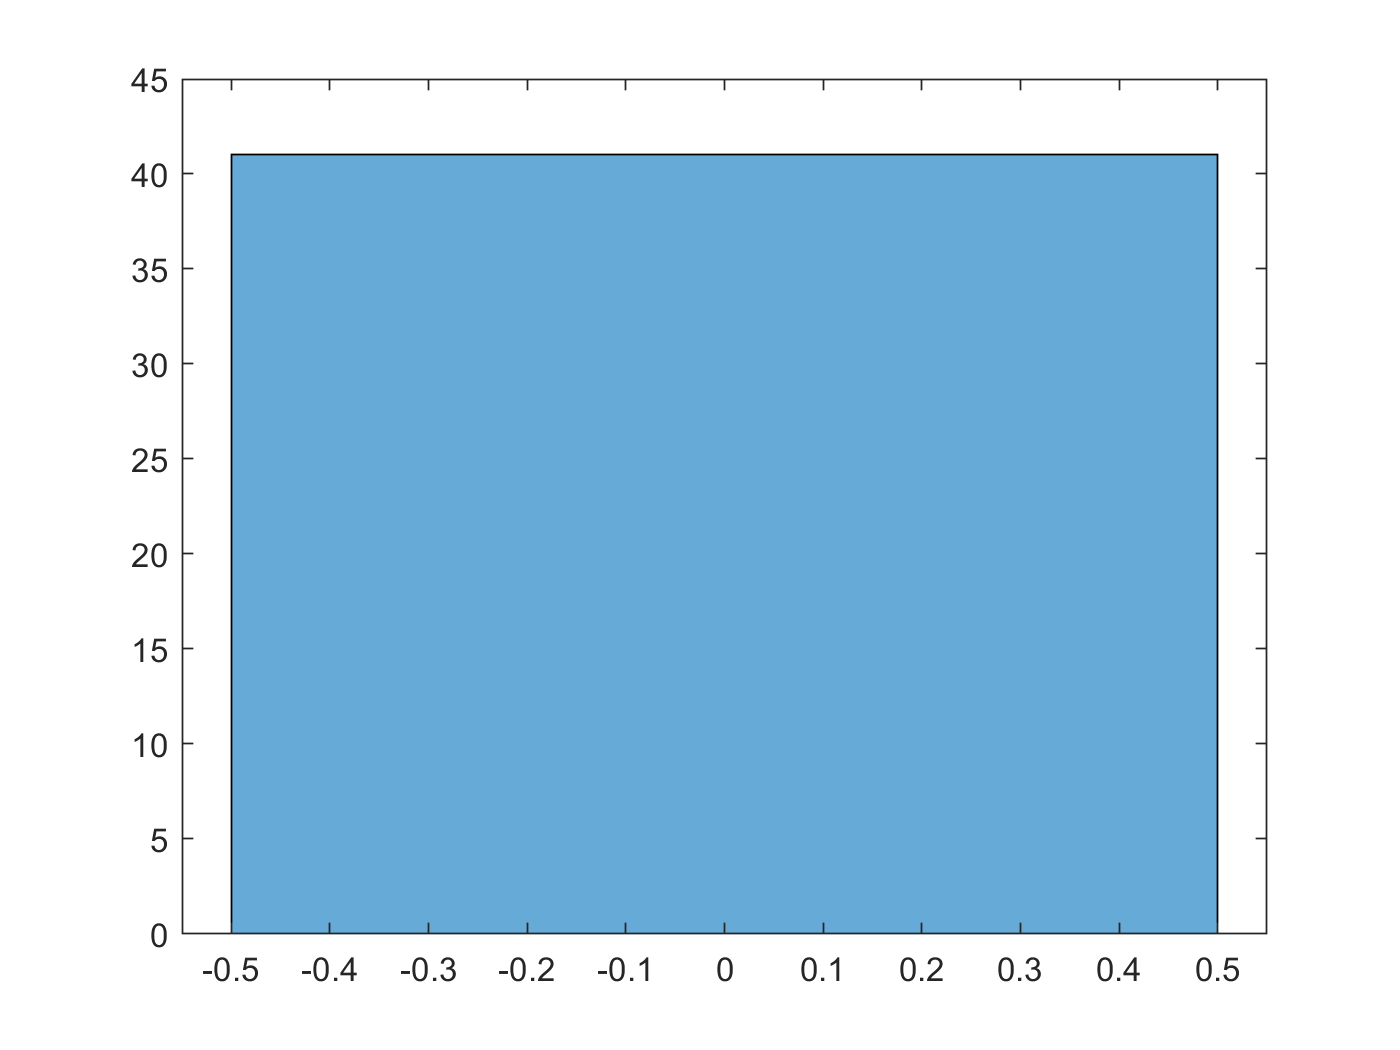

(y - yhat).^2 ;  % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 3.2407e-09

training set (b1,2)로 b2 예측 - 정확함.

% predict batch2 from model from model
idx = idx2;
Ic_ = [BAT(idx).Ic];
x = (reshape(Ic_,100,[]))';
y = [BAT(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat =   299.0000
  147.0000
  437.0000
  334.0000
  443.0000
  479.0000
  510.0000
  560.0000
  476.0000
  457.0000


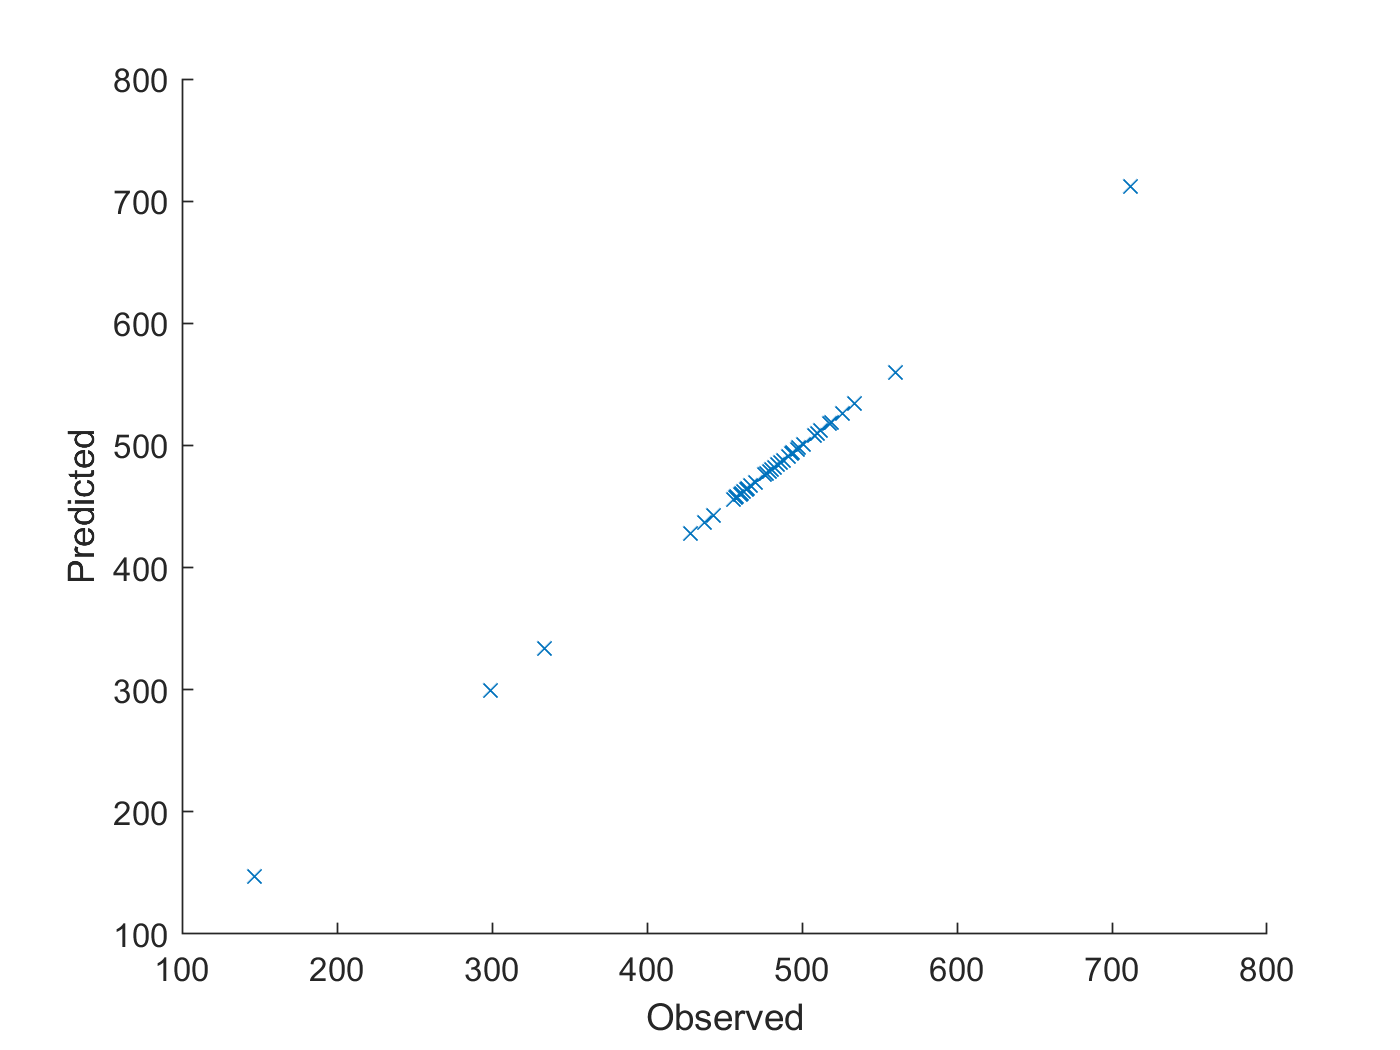

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+-8 *

   -0.1712
   -0.3099
   -0.1932
   -0.2471
   -0.2570
   -0.2114
   -0.0862
   -0.2546
   -0.1707
   -0.1222


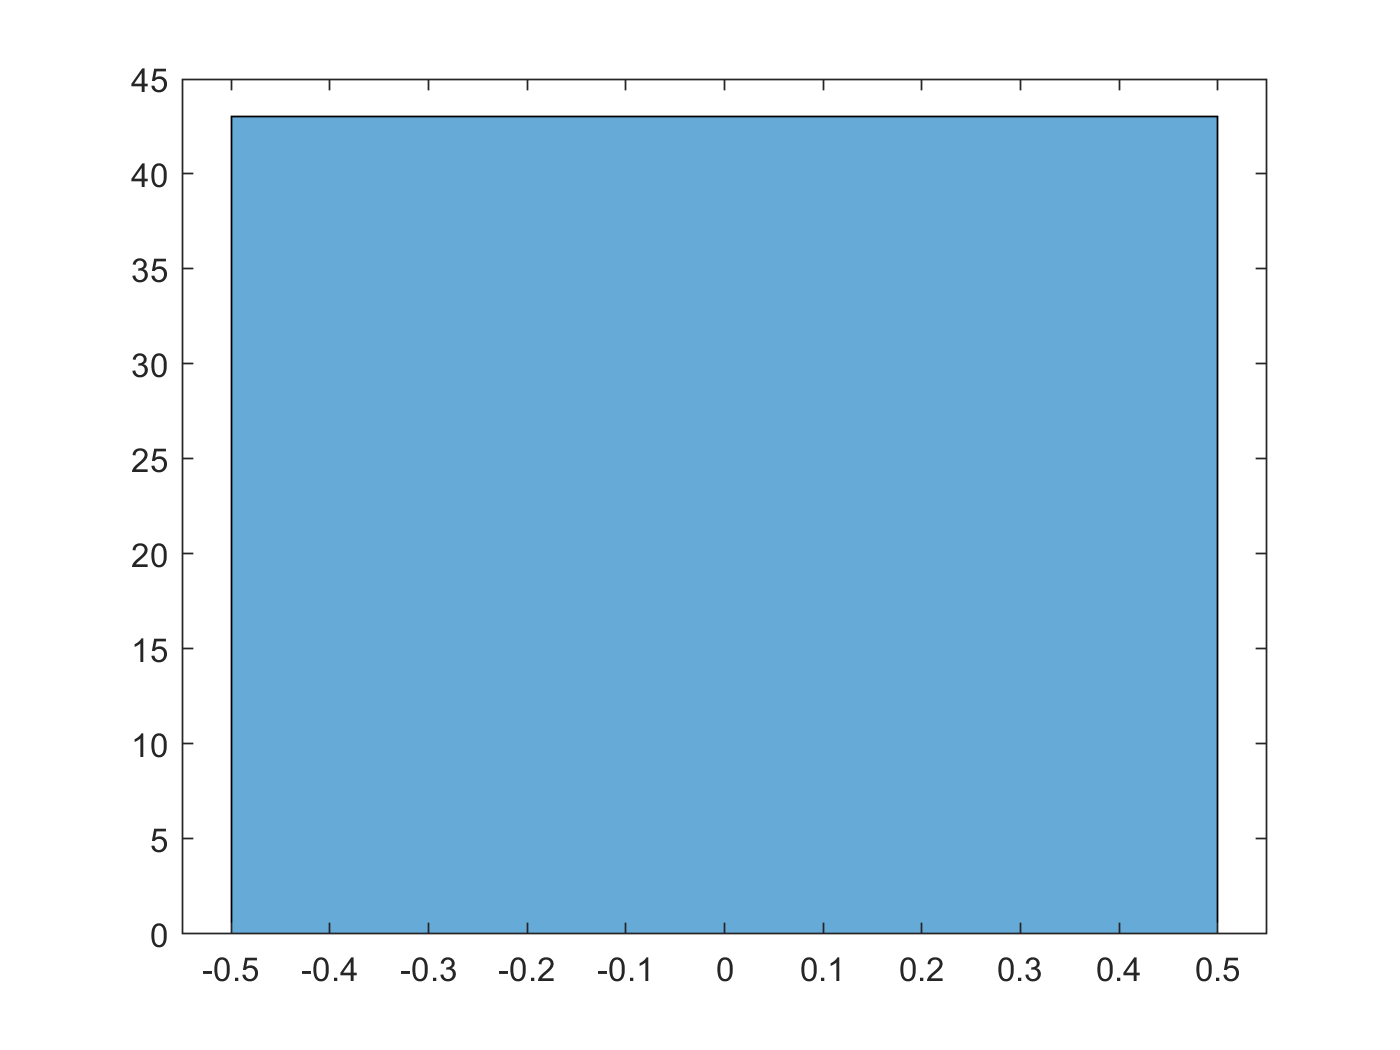

(y - yhat).^2 ;  % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 2.3242e-09

training set (b1,2)로 test set b3 예측 - RMSE가 매우 큼

% predict batch3 from model from model
idx = idx3;
Ic_ = [BAT(idx).Ic];
x = (reshape(Ic_,100,[]))';
y = [BAT(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat = 	1.0e+05 *

   -0.7818
    1.3601
   -2.3928
    4.8755
   -2.4035
   -0.0329
   -0.0043
   -0.6031
    1.3586
    0.0245


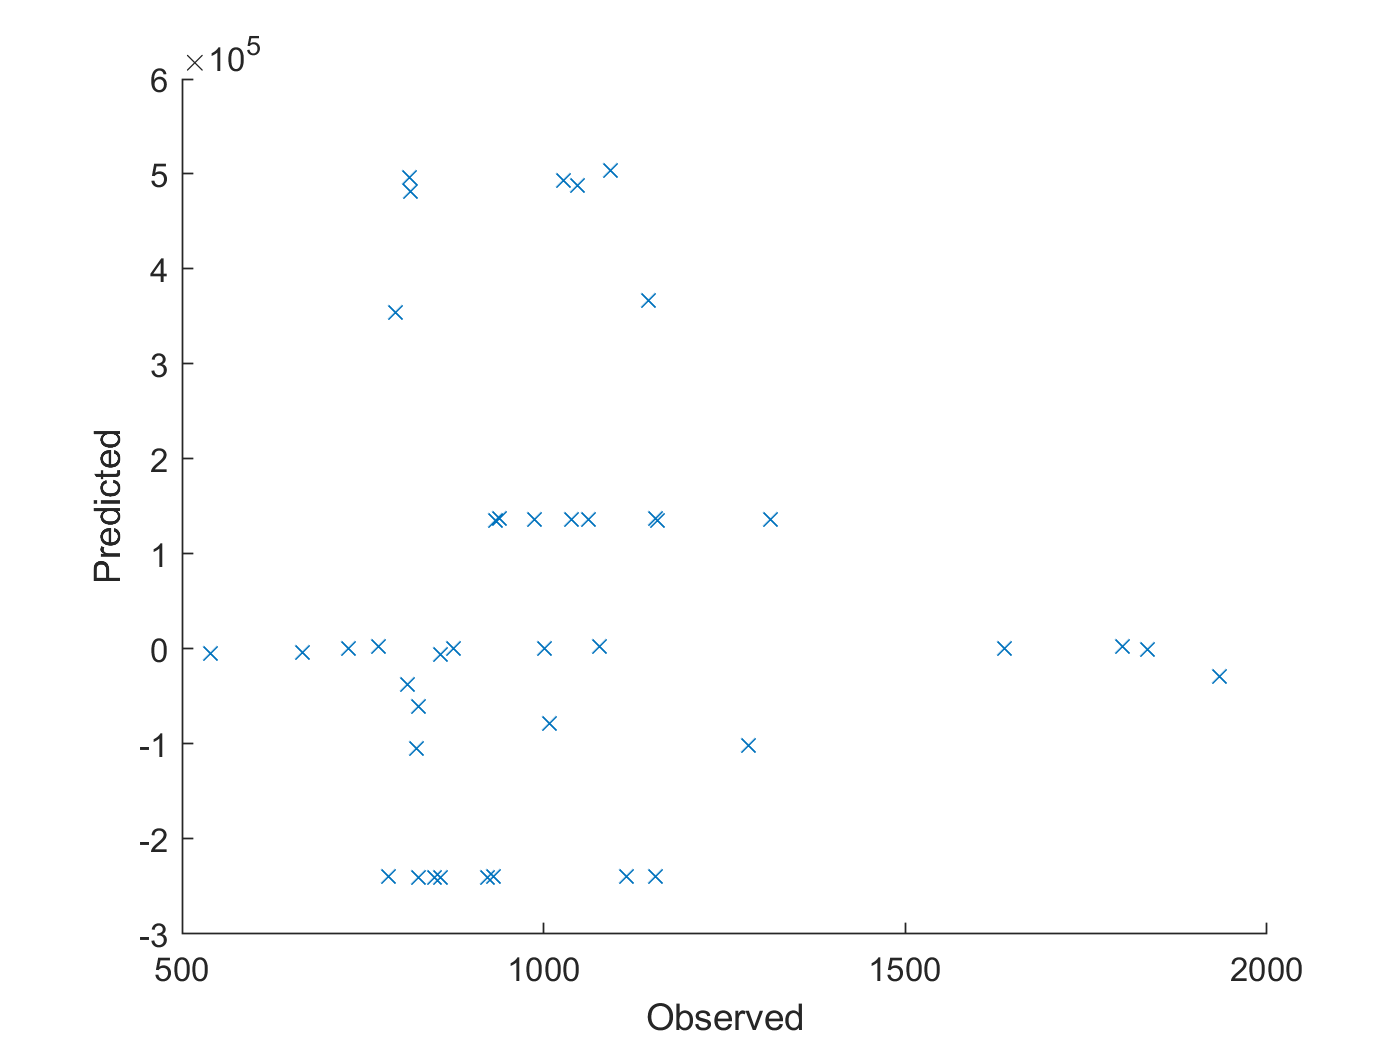

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+05 *

    0.7919
   -1.3495
    2.4039
   -4.8650
    2.4118
    0.0396
    0.0227
    0.6113
   -1.3483
   -0.0137


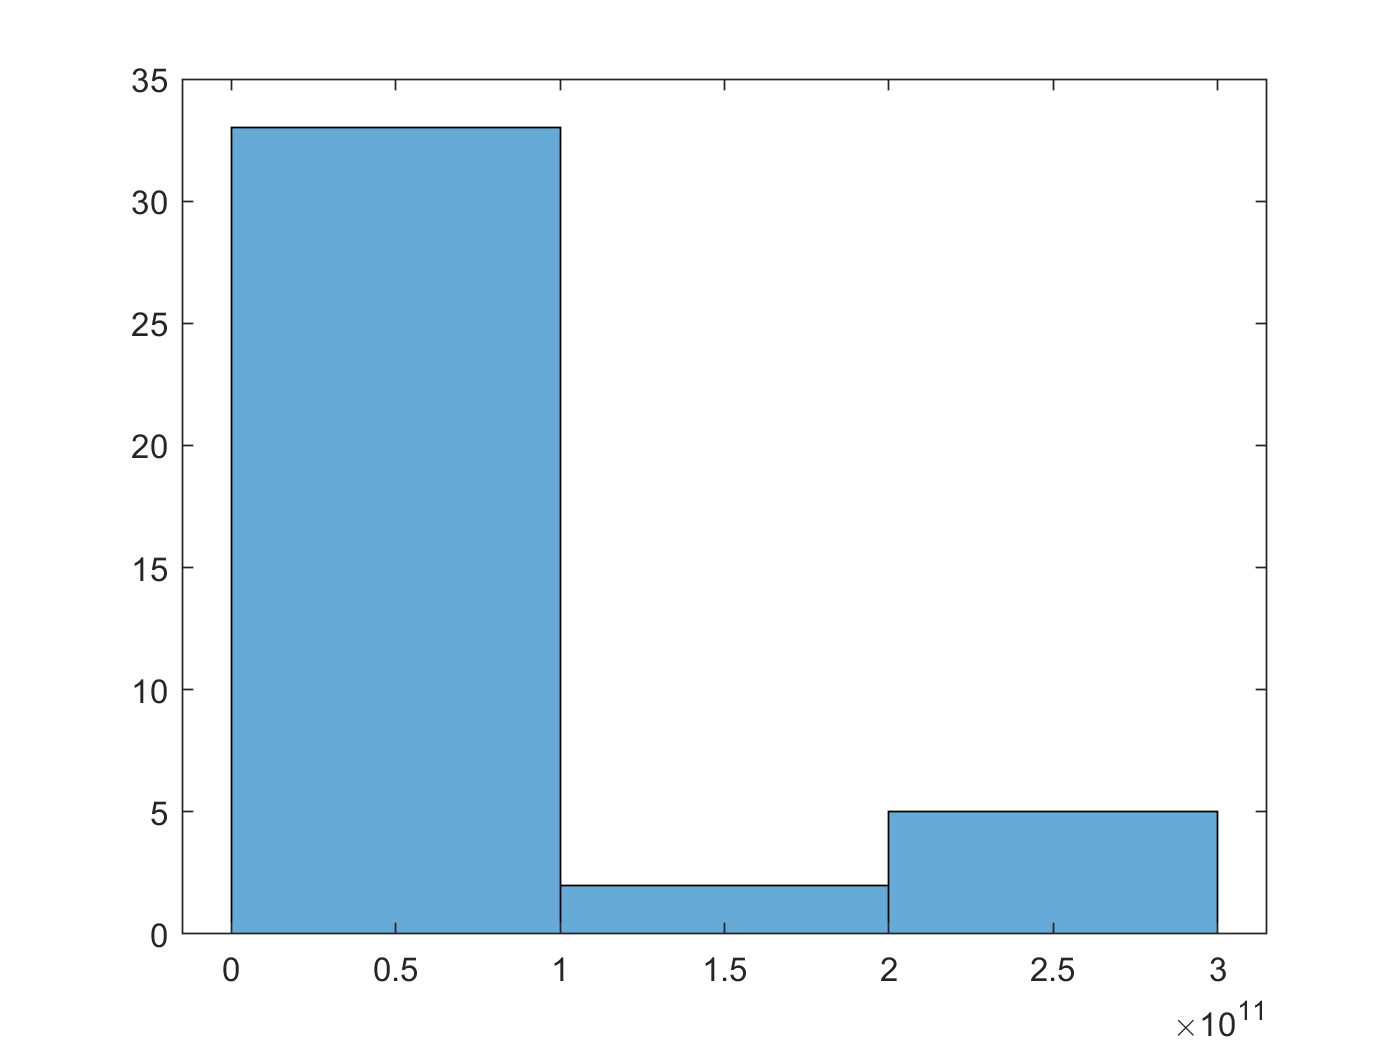

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 2.2967e+05

%%%%
% 선형회귀에서는 trainng set 에서는 잘 동작하나 test set인 batch3 에서는 오차가 크다.


머신러닝 방법을 사용하기 위해 데이타 정규화.

이때 test set 에서도 동일한 범위로 동작하기 위해 모든 데이타에 대해 한번에 정규화해야 함.

ynorm,xnorm = training set

ytestnorm,xtestnorm = test set

idx = idxAll;
y = [BAT(idx).cycle_life ]';
x = (reshape([BAT(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);


%%% LSTM 회귀
%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 
idxtest = idx3 ; % training set - 
%idx = idx1;
key = [BAT(idx).key]';
% s1 = string([{BAT(idx).policy}])
% policy = [{BAT(idx).policy}]';
% policy_str = string([{BAT(idx).policy}]');
% policy_readable = [{BAT(idx).policy_readable}]';
% policy_readable_str = string([{BAT(idx).policy_readable}]');
%Ic1 = [{BAT(idx).Ic}]';
%Ic_ = [BAT(idx).Ic];
%Ic__ = reshape(Ic_,100,length(policy));
%Ic = Ic__';
y = [BAT(idx).cycle_life ]';
x_input_size = 100;
x = (reshape([BAT(idx).Ic],x_input_size,length(y)))';

keytest = [BAT(idxtest).key]';
ytest = [BAT(idxtest).cycle_life ]';
xtest = (reshape([BAT(idxtest).Ic],x_input_size,length(ytest)))';

[ynorm,xnorm] = norm_with(y,x,ymax,ymin,xmax,xmin);
[ytestnorm,xtestnorm] = norm_with(ytest,xtest,ymax,ymin,xmax,xmin);

% Train_Input = x;
% Train_Output = y;
% Test_Input = xtest;
% Test_Output = ytest;

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

netFNN = feedforwardnet([50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN.divideFcn = ''; % 모두 train에만 사용
% netFNN.divideParam.trainInd = 1:length(ynorm);
%  netFNN.divideParam.valInd = [];
%  netFNN.divideParam.testInd = [];
% netFNN40.trainParam.epochs = 100; %300;
netFNN.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN.trainParam.show = NaN;
[netFNN, tr] = train(netFNN, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


view(netFNN)

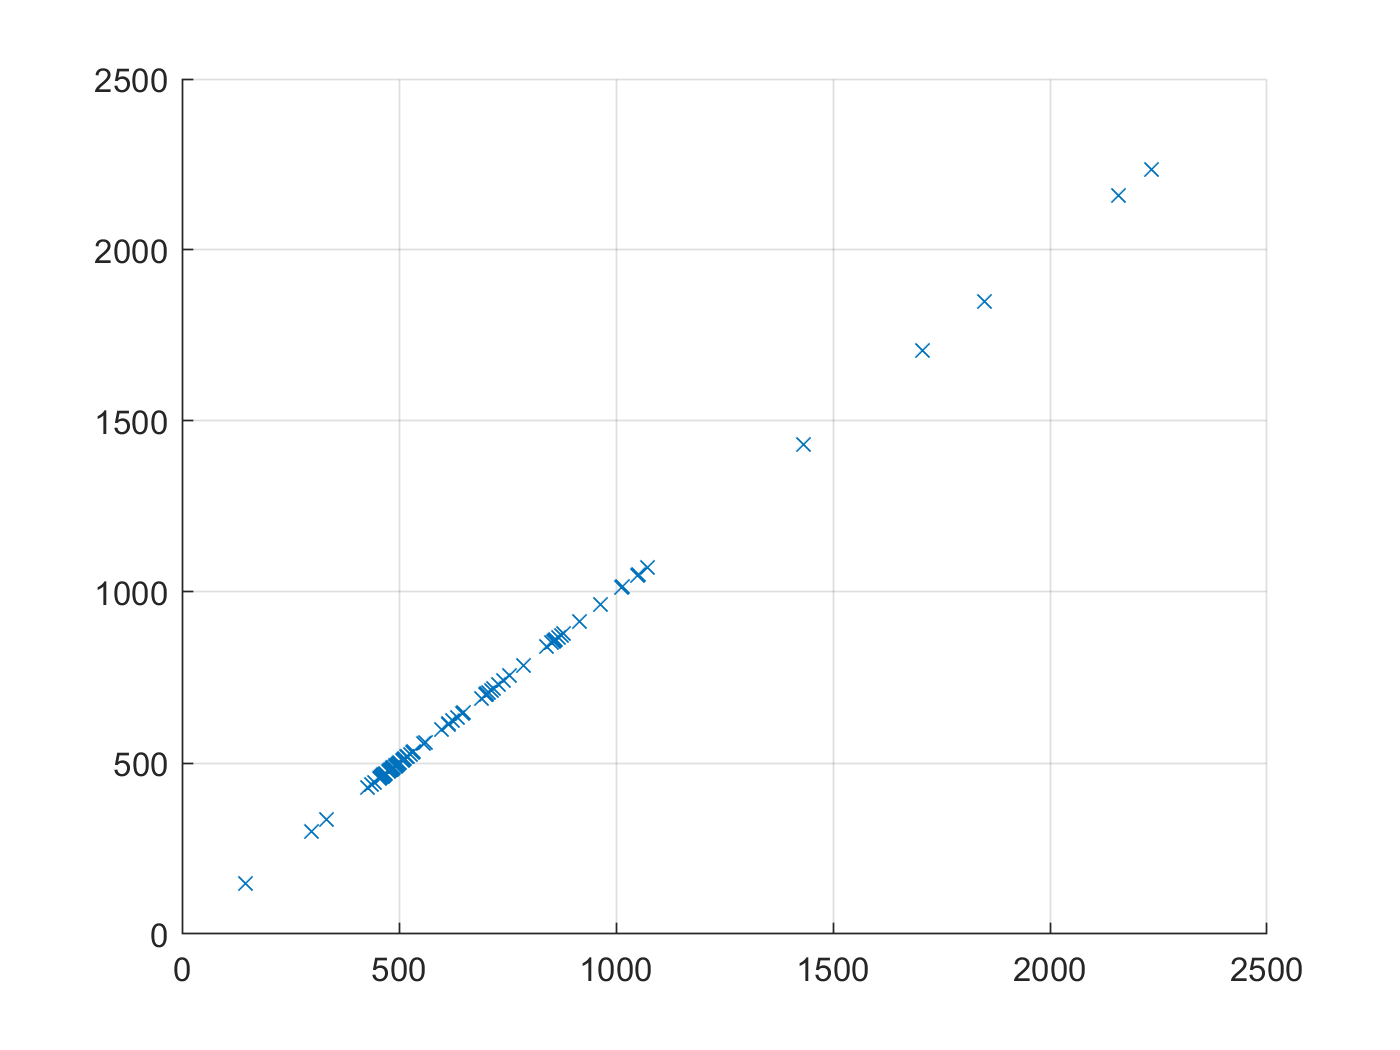

%%%%%%%%%%%% 학습한 데이타로 검증
ynorm_hat_netFNN = netFNN(xnorm')';
total_cycle = length(ynorm_hat_netFNN);
y_hat_netFNN = ynorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(y,y_hat_netFNN,'x')
hold off

%{
ynorm_hat_netFNN = netFNN(xnorm(tr.testInd, :)')';
total_cycle = length(ynorm_hat_netFNN);
y_hat_netFNN = ynorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(y(tr.testInd),y_hat_netFNN,'x')
hold off
%}

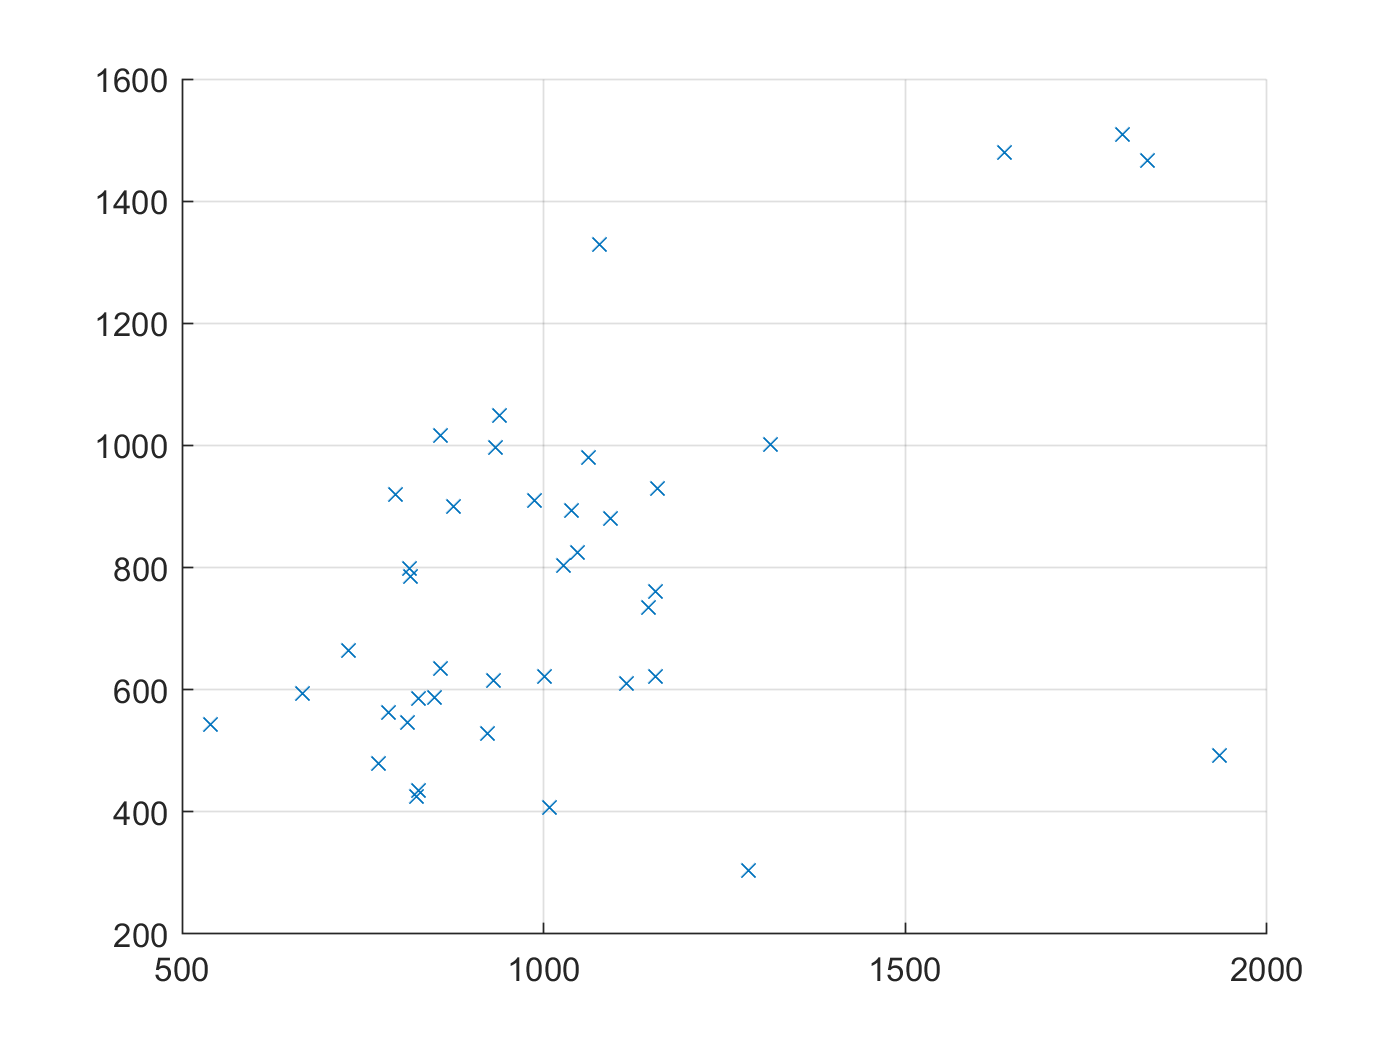


%%%%%%%%%%%%%

ytestnorm_hat_netFNN = netFNN(xtestnorm')';
total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(ytest,ytest_hat_netFNN,'x')
hold off

CNN을 위해 충전전류를 2차원 이미지로 만들기

ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate

a = xtestnorm(1,:)

a =          0    0.6248    0.6248    0.6245    0.6245    0.6246    0.6245    0.6245    0.6246    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6246    0.6245    0.6246    0.6245    0.6246    0.6245    0.6245    0.6244    0.6245    0.6245    0.6245    0.6245    0.6244    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6244    0.6246    0.6245    0.6245    0.6244    0.6245    0.6244    0.6244    0.6244    0.6245    0.6244    0.6244    0.6244    0.6243    0.6243


b = zeros(100,100);
c = round(xtestnorm(1,:)* 100)

c =      0    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62


for i=1:100
    b(i,c(i)+1)=1;
end
b

b =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


xxx = [1:100]

xxx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



space = [ 1:100]

space =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


new_space = [1:28]

new_space =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


new_xxx = interp1(space,xxx,new_space,'linear')

new_xxx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


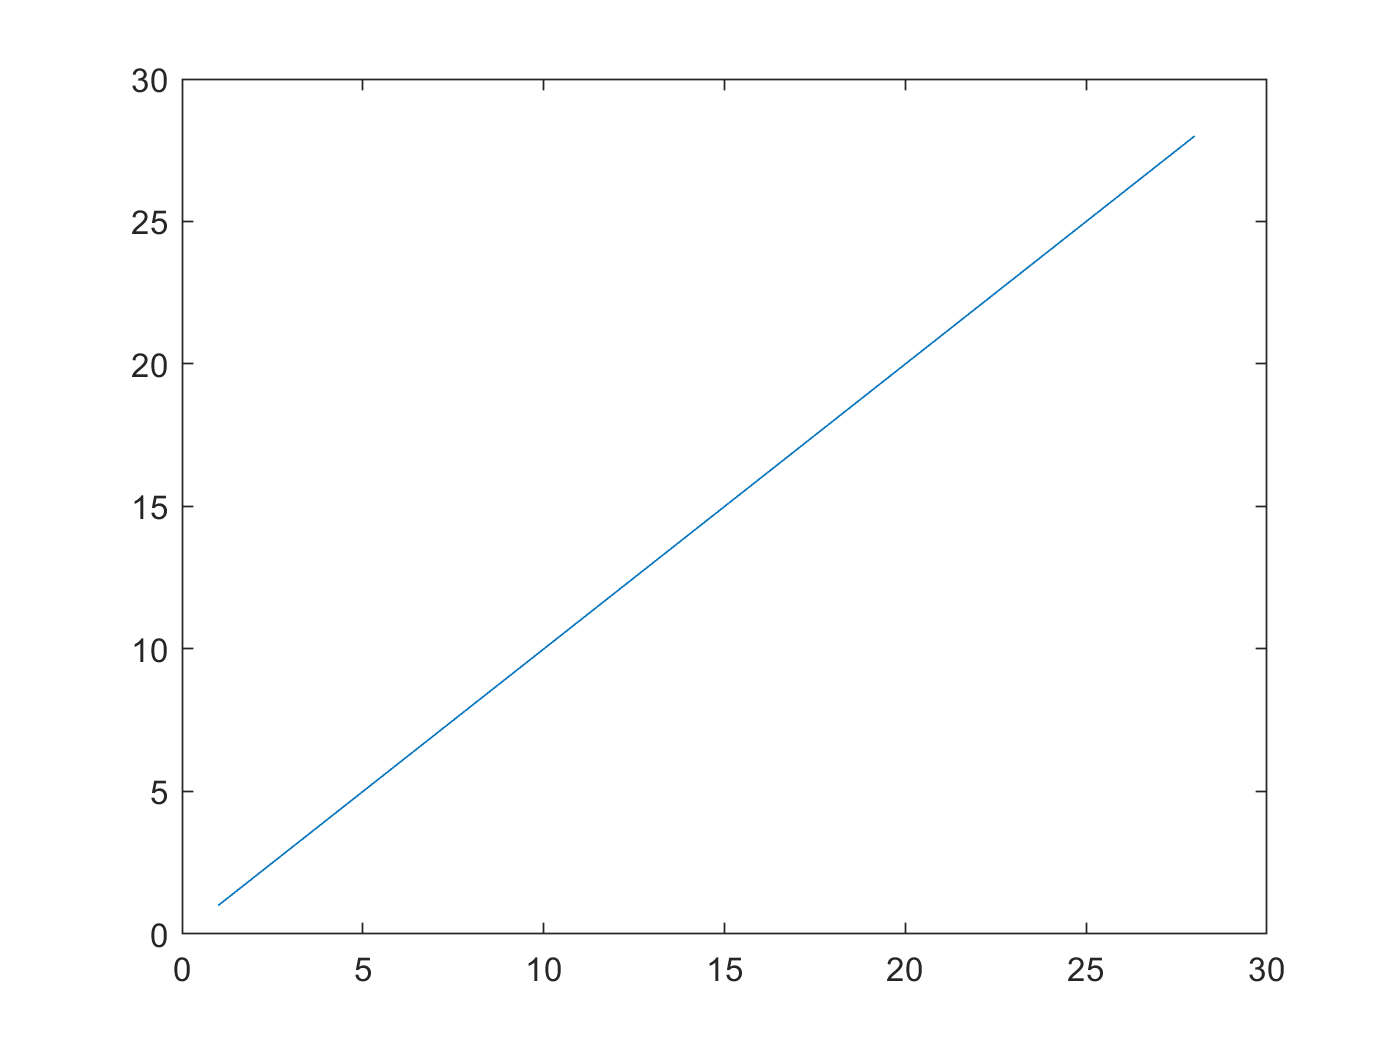

figure
plot(new_xxx)

%{
plot_max_x = 28;
plot_max_y = 28 ;

%a = 
%x = 
xx_max = 28
y_max = 28
rows = max(xtestnorm(1,:));
columns = length(yo);
outputImage = false(rows, columns);
for k = 1 : columns
  outputImage(yo(k), k) = true;
end
imshow(outputImage);

%}

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |         0.30 |      4.6e-02 |          0.0010 |
|      50 |          50 |       00:00:11 |         0.16 |      1.3e-02 |          0.0010 |
|     100 |         100 |       00:00:12 |         0.08 |      3.0e-03 |          0.0010 |
|     150 |         150 |       00:00:13 |         0.05 |      1.4e-03 |          0.0010 |
|     200 |         200 |       00:00:15 |         0.04 |      9.6e-04 |          0.0010 |
|     250 |         250 |       00:00:17 |         0.04 |      6.8e-04 |          0.0010 |
|     300 |         300 |  

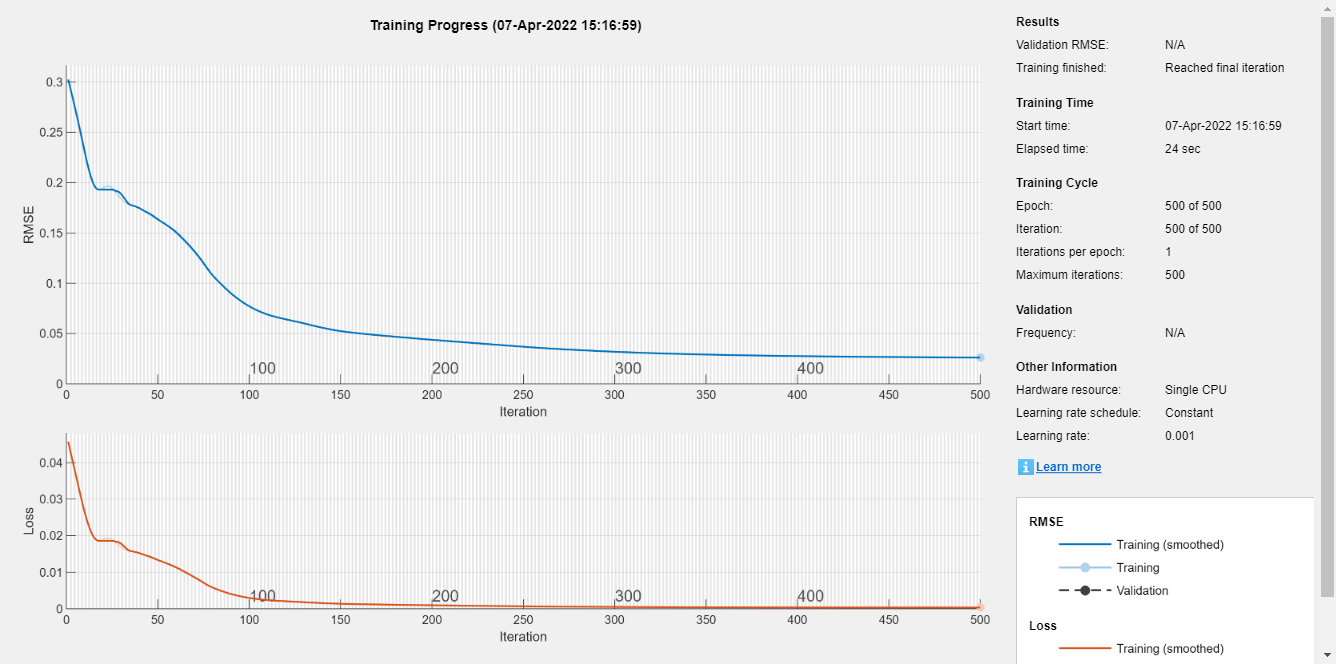

input_size = 100;
layerCNN1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;

% Traintbl = tbl(tr.trainInd, :);
% valtbl = tbl(tr.valInd, :);
% testtbl = tbl(tr.testInd, :);

% options = trainingOptions('adam', ...
%     'InitialLearnRate', 0.001, ...
%     'MaxEpochs',500, ...
%     'MiniBatchSize',50, ...
%     'Plots','training-progress', 'ValidationData', valtbl);




options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress');

%netCNN1 = trainNetwork(Traintbl, layerCNN1, options);
netCNN1 = trainNetwork(tbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         0.37 |      6.8e-02 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.10 |      5.4e-03 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.08 |      3.0e-03 |          0.0010 |
|     150 |         150 |       00:00:12 |         0.07 |      2.2e-03 |          0.0010 |
|     200 |         200 |       00:00:14 |         0.06 |      1.6e-03 |          0.0010 |
|     250 |         250 |       00:00:15 |         0.05 |      1.1e-03 |          0.0010 |
|     300 |         300 |  

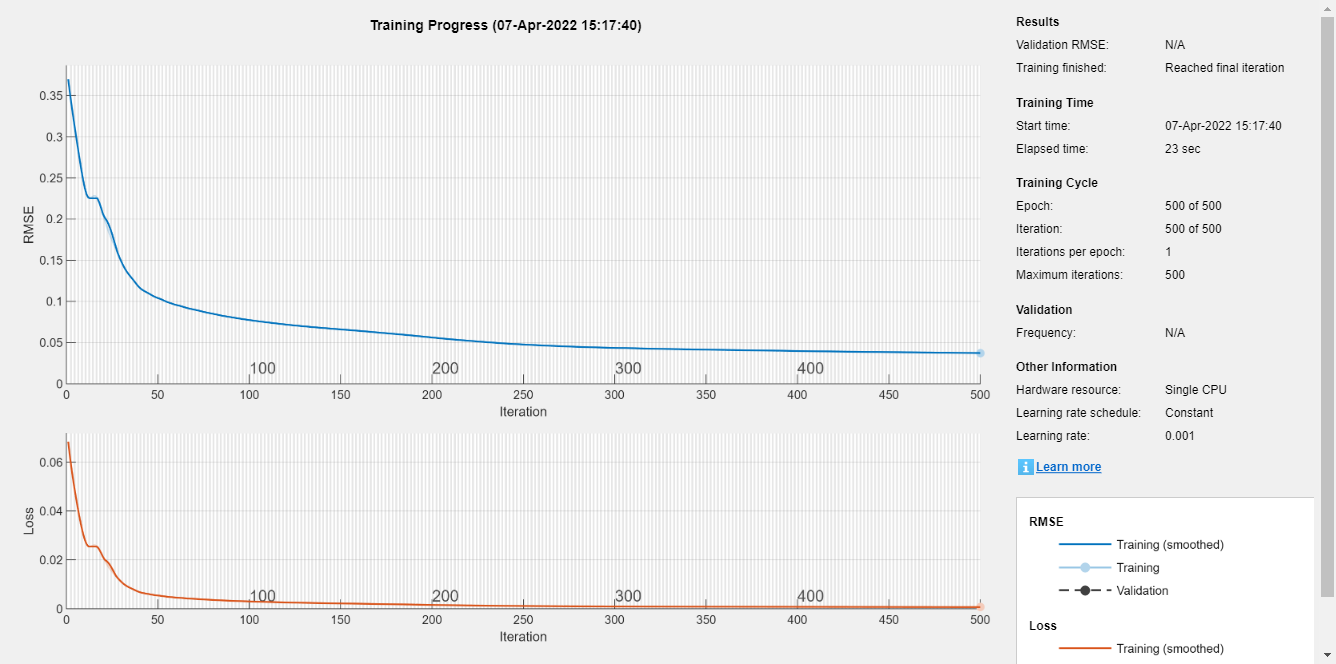

layerCNN2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
%netCNN2 = trainNetwork(Traintbl, layerCNN2, options);
netCNN2 = trainNetwork(tbl, layerCNN2, options);

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         0.43 |      9.4e-02 |          0.0010 |
|      50 |          50 |       00:00:10 |         0.20 |      2.0e-02 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.18 |      1.6e-02 |          0.0010 |
|     150 |         150 |       00:00:13 |         0.16 |      1.2e-02 |          0.0010 |
|     200 |         200 |       00:00:14 |         0.13 |      8.6e-03 |          0.0010 |
|     250 |         250 |       00:00:15 |         0.11 |      6.0e-03 |          0.0010 |
|     300 |         300 |       00:00:16 |         0.09 |      4.2

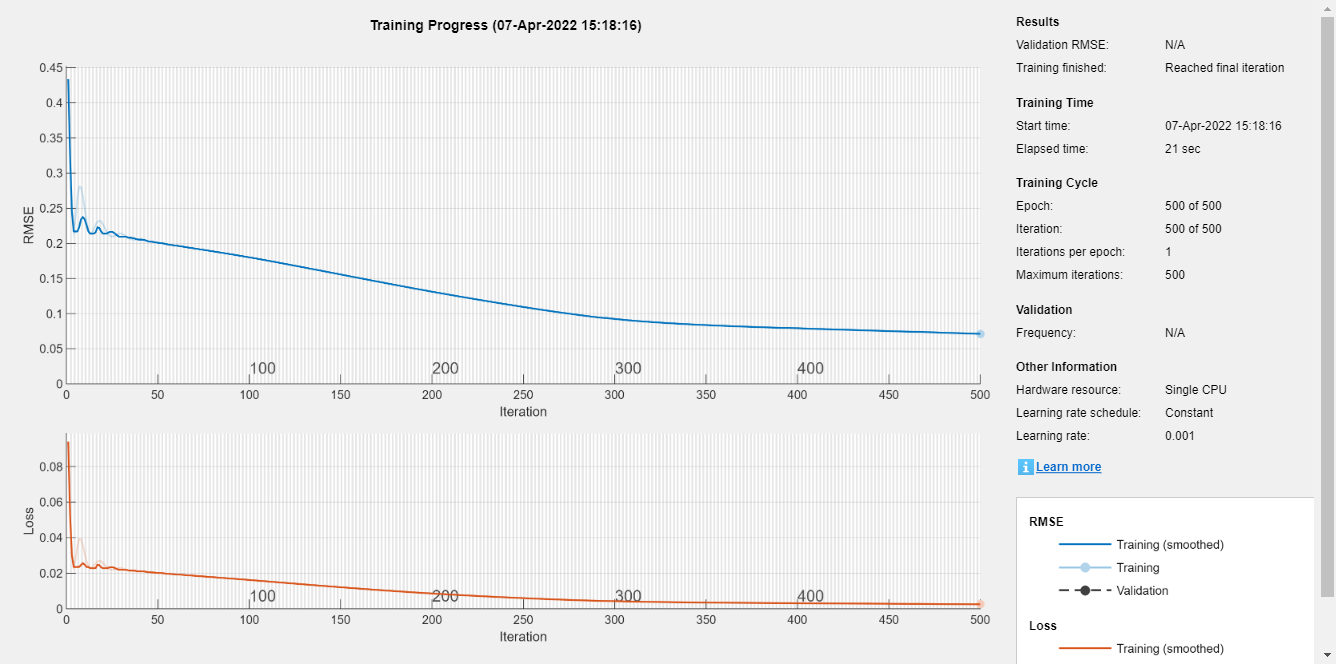

numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

% options = trainingOptions('adam', ...
%     'InitialLearnRate', 0.001, ...
%     'MaxEpochs',500, ...
%     'MiniBatchSize',50, ...
%     'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress');

% netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);
netLSTM = trainNetwork(cellx, cellyB, layersLSTM, options);

ytestnorm_hat_netFNN = netFNN(xtestnorm')';
total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(ytest,ytest_hat_netFNN,'x')
hold off


pCNN1 = predict(netCNN1, x_4d);
pCNN2 = predict(netCNN2, x_4d);
pLSTM = cell2mat(predict(netLSTM, num2cell(xtestnorm', 1)));

ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;


%{
modelspec = ' cycle ~ Ic ';
mdl = fitlm(cycleTable,modelspec )
%}

% 사이클이 긴것부터 키를 출력하자.
new_struct = struct();
for i=1:length(BAT)
    new_struct(i).key = BAT(i).key

end

new_struct = struct with fields:
    key: "b1c1"


new_struct = 1×2 struct array with fields:
    key


new_struct = 1×3 struct array with fields:
    key


new_struct = 1×4 struct array with fields:
    key


new_struct = 1×5 struct array with fields:
    key


new_struct = 1×6 struct array with fields:
    key


new_struct = 1×7 struct array with fields:
    key


new_struct = 1×8 struct array with fields:
    key


new_struct = 1×9 struct array with fields:
    key


new_struct = 1×10 struct array with fields:
    key


new_struct = 1×11 struct array with fields:
    key


new_struct = 1×12 struct array with fields:
    key


new_struct = 1×13 struct array with fields:
    key


new_struct = 1×14 struct array with fields:
    key


new_struct = 1×15 struct array with fields:
    key


new_struct = 1×16 struct array with fields:
    key


new_struct = 1×17 struct array with fields:
    key


new_struct = 1×18 struct array with fields:
    key


new_struct = 1×19 struct array with fields:
    key


new_struct = 1×20 struct array with fields:
    key


new_struct = 1×21 struct array with fields:
    key


new_struct = 1×22 struct array with fields:
    key


new_struct = 1×23 struct array with fields:
    key


new_struct = 1×24 struct array with fields:
    key


new_struct = 1×25 struct array with fields:
    key


new_struct = 1×26 struct array with fields:
    key


new_struct = 1×27 struct array with fields:
    key


new_struct = 1×28 struct array with fields:
    key


new_struct = 1×29 struct array with fields:
    key


new_struct = 1×30 struct array with fields:
    key


new_struct = 1×31 struct array with fields:
    key


new_struct = 1×32 struct array with fields:
    key


new_struct = 1×33 struct array with fields:
    key


new_struct = 1×34 struct array with fields:
    key


new_struct = 1×35 struct array with fields:
    key


new_struct = 1×36 struct array with fields:
    key


new_struct = 1×37 struct array with fields:
    key


new_struct = 1×38 struct array with fields:
    key


new_struct = 1×39 struct array with fields:
    key


new_struct = 1×40 struct array with fields:
    key


new_struct = 1×41 struct array with fields:
    key


new_struct = 1×42 struct array with fields:
    key


new_struct = 1×43 struct array with fields:
    key


new_struct = 1×44 struct array with fields:
    key


new_struct = 1×45 struct array with fields:
    key


new_struct = 1×46 struct array with fields:
    key


new_struct = 1×47 struct array with fields:
    key


new_struct = 1×48 struct array with fields:
    key


new_struct = 1×49 struct array with fields:
    key


new_struct = 1×50 struct array with fields:
    key


new_struct = 1×51 struct array with fields:
    key


new_struct = 1×52 struct array with fields:
    key


new_struct = 1×53 struct array with fields:
    key


new_struct = 1×54 struct array with fields:
    key


new_struct = 1×55 struct array with fields:
    key


new_struct = 1×56 struct array with fields:
    key


new_struct = 1×57 struct array with fields:
    key


new_struct = 1×58 struct array with fields:
    key


new_struct = 1×59 struct array with fields:
    key


new_struct = 1×60 struct array with fields:
    key


new_struct = 1×61 struct array with fields:
    key


new_struct = 1×62 struct array with fields:
    key


new_struct = 1×63 struct array with fields:
    key


new_struct = 1×64 struct array with fields:
    key


new_struct = 1×65 struct array with fields:
    key


new_struct = 1×66 struct array with fields:
    key


new_struct = 1×67 struct array with fields:
    key


new_struct = 1×68 struct array with fields:
    key


new_struct = 1×69 struct array with fields:
    key


new_struct = 1×70 struct array with fields:
    key


new_struct = 1×71 struct array with fields:
    key


new_struct = 1×72 struct array with fields:
    key


new_struct = 1×73 struct array with fields:
    key


new_struct = 1×74 struct array with fields:
    key


new_struct = 1×75 struct array with fields:
    key


new_struct = 1×76 struct array with fields:
    key


new_struct = 1×77 struct array with fields:
    key


new_struct = 1×78 struct array with fields:
    key


new_struct = 1×79 struct array with fields:
    key


new_struct = 1×80 struct array with fields:
    key


new_struct = 1×81 struct array with fields:
    key


new_struct = 1×82 struct array with fields:
    key


new_struct = 1×83 struct array with fields:
    key


new_struct = 1×84 struct array with fields:
    key


new_struct = 1×85 struct array with fields:
    key


new_struct = 1×86 struct array with fields:
    key


new_struct = 1×87 struct array with fields:
    key


new_struct = 1×88 struct array with fields:
    key


new_struct = 1×89 struct array with fields:
    key


new_struct = 1×90 struct array with fields:
    key


new_struct = 1×91 struct array with fields:
    key


new_struct = 1×92 struct array with fields:
    key


new_struct = 1×93 struct array with fields:
    key


new_struct = 1×94 struct array with fields:
    key


new_struct = 1×95 struct array with fields:
    key


new_struct = 1×96 struct array with fields:
    key


new_struct = 1×97 struct array with fields:
    key


new_struct = 1×98 struct array with fields:
    key


new_struct = 1×99 struct array with fields:
    key


new_struct = 1×100 struct array with fields:
    key


new_struct = 1×101 struct array with fields:
    key


new_struct = 1×102 struct array with fields:
    key


new_struct = 1×103 struct array with fields:
    key


new_struct = 1×104 struct array with fields:
    key


new_struct = 1×105 struct array with fields:
    key


new_struct = 1×106 struct array with fields:
    key


new_struct = 1×107 struct array with fields:
    key


new_struct = 1×108 struct array with fields:
    key


new_struct = 1×109 struct array with fields:
    key


new_struct = 1×110 struct array with fields:
    key


new_struct = 1×111 struct array with fields:
    key


new_struct = 1×112 struct array with fields:
    key


new_struct = 1×113 struct array with fields:
    key


new_struct = 1×114 struct array with fields:
    key


new_struct = 1×115 struct array with fields:
    key


new_struct = 1×116 struct array with fields:
    key


new_struct = 1×117 struct array with fields:
    key


new_struct = 1×118 struct array with fields:
    key


new_struct = 1×119 struct array with fields:
    key


new_struct = 1×120 struct array with fields:
    key


new_struct = 1×121 struct array with fields:
    key


new_struct = 1×122 struct array with fields:
    key


new_struct = 1×123 struct array with fields:
    key


new_struct = 1×124 struct array with fields:
    key


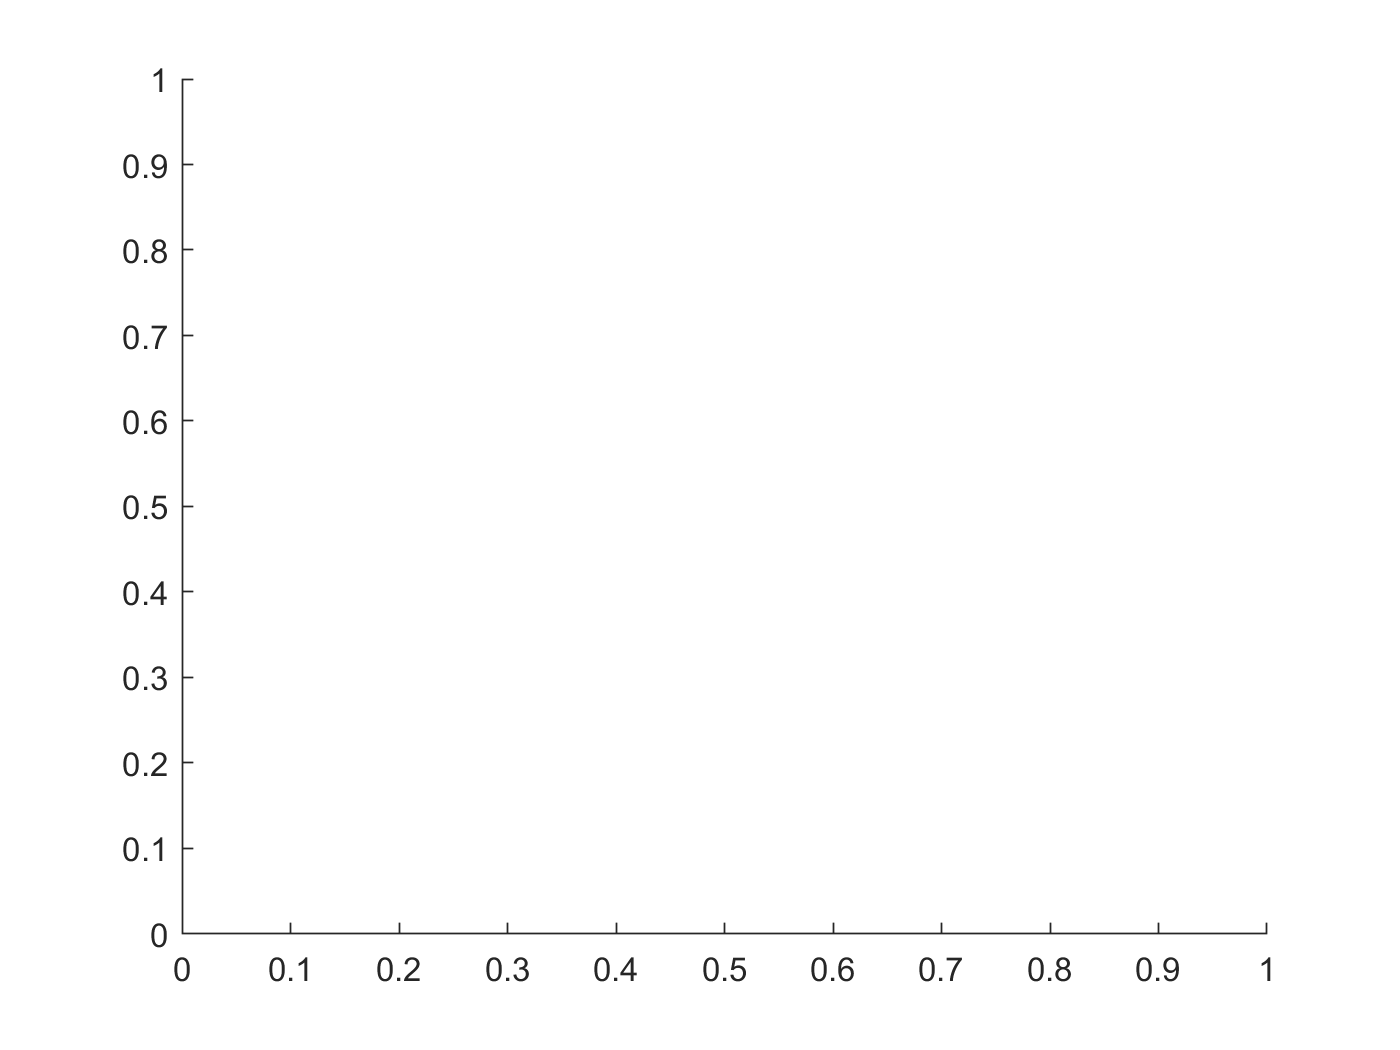

i =1;
figure
hold on

plot(newbat(i).cycle,newbat_org(1).QDischarge)

Unrecognized function or variable 'newbat'.

plot(BAT(bat2_num(i)).cycle,BAT(bat2_num(i)).QDischarge)

hold off
% Vd Qc
figure
hold on
plot(newbat_org(1).Qc)
plot(BAT(bat2_num(i)).Qc)
hold off



for i=1:length(bat2_num)
    %newbat(i).cycle_life = 
    newbat(i).cycle_life;
    BAT(bat2_num(i)).cycle_life;
    newbat(i).cycle_life = newbat(i).cycle_life + BAT(bat2_num(i)).cycle_life;
    newbat(i).cycle = linspace(1,newbat(i).cycle_life,newbat(i).cycle_life);
    newbat(i).chargetime = vertcat(newbat(i).chargetime,BAT(bat2_num(i)).chargetime);
    newbat(i).IR = vertcat(newbat(i).IR,BAT(bat2_num(i)).IR);
    newbat(i).QCharge = vertcat(newbat(i).QCharge,BAT(bat2_num(i)).QCharge);
    newbat(i).QDischarge = vertcat(newbat(i).QDischarge,BAT(bat2_num(i)).QDischarge);
    newbat(i).Tavg = vertcat(newbat(i).Tavg,BAT(bat2_num(i)).Tavg);
    newbat(i).Tmin = vertcat(newbat(i).Tmin,BAT(bat2_num(i)).Tmin);
    newbat(i).Tmax = vertcat(newbat(i).Tmax,BAT(bat2_num(i)).Tmax);
    newbat(i).Vdlin = vertcat(newbat(i).Vdlin,BAT(bat2_num(i)).Vdlin);
    newbat(i).Vc = horzcat(newbat(i).Vc,BAT(bat2_num(i)).Vc);
    newbat(i).Tc = horzcat(newbat(i).Tc,BAT(bat2_num(i)).Tc);
    newbat(i).Vd = horzcat(newbat(i).Vd,BAT(bat2_num(i)).Vd);
    newbat(i).Td = horzcat(newbat(i).Td,BAT(bat2_num(i)).Td);
    newbat(i).QDischargeSmooth = horzcat(newbat(i).QDischargeSmooth,BAT(bat2_num(i)).QDischargeSmooth);
    %newbat(i).QDischargePolyMdl = vertcat(newbat(i).QDischargePolyMdl,BAT(bat2_num(i)).QDischargePolyMdl);
    %newbat(i).QDischargePolyfit = vertcat(newbat(i).QDischargePolyfit,BAT(bat2_num(i)).QDischargePolyfit);
   
end

new_index = 1;
batchNum = 1;
clear batch1_info;
clear batch1_data;

max_cycle=1;
for batNum = 1:size(trainData,2);
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if trainData(batNum).cycle_life > max_cycle 
            max_cycle = trainData(batNum).cycle_life;
        end
    end
end
max_cycle = max_cycle-1;



ignore = [];
ignore_index =1;
figure, hold on;
%trainData_cycle= zeros() %1,size(trainData,2));
%trainData_QDischarge= zeros(1,size(trainData,2));

new_index = 1;
for i = 1:size(trainData,2)
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);     
      %trainData_cycle(new_index) = trainData(i).summary.cycle;
      %trainData_cycle = [ trainData_cycle' ; trainData(i).summary.cycle' ];
      %trainData_QDischarge(new_index) = trainData(i).summary.QDischarge;
      %new_index = new_index+1;
    else
      ignore(ignore_index) = i;
      ignore_index = ignore_index +1;
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');


% #batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))
% batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))
% #remove batteries that do not reach 80% capacity
% del batch1['b1c8']
% del batch1['b1c10']
% del batch1['b1c12']
% del batch1['b1c13']
% del batch1['b1c22']

skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index


batch1 = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));
batch1(1) = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));
batch1(2) = extract_feature_all_new_bat_soc_v3(1,2,trainData(2));


figure
hold on

plot(batch1(1).cycle(20:end),batch1(1).QDischarge(20:end))
plot(batch1(2).cycle(20:end),batch1(2).QDischarge(20:end))    

Idx = batch1(1).QDischarge > 1.3;

plot(batch1(1).cycle,batch1(1).QDischargeSmooth)
plot(batch1(2).cycle,batch1(2).QDischargeSmooth) 

% plot(batch1(1).cycle,batch1(1).QChargePolyfit)
% plot(batch1(2).cycle,batch1(2).QChargePolyfit) 

hold off

figure
hold on
plot(batch(1).cycle,batch(1).QDischarge)
plot(batch(2).cycle,batch(2).QDischarge)
hold off

figure
hold on
plot(batch(1).cycle,batch(1).QDischargeSmooth)
plot(batch(2).cycle,batch(2).QDischargeSmooth)
hold off
figure
hold on
plot(batch(1).cycle,batch(1).QDischargePolyfit)
plot(batch(2).cycle,batch(2).QDoschargePolyfit)
hold off

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

batchNum = 2;


for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,continue_batch2) 
            batNum;
        end    

            batch(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            

    else
        batNum;
    end
end

% #batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))
% batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))
% #remove batteries that do not reach 80% capacity
% del batch1['b1c8']
% del batch1['b1c10']
% del batch1['b1c12']
% del batch1['b1c13']
% del batch1['b1c22']

skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

continue_batch2 = [7 8 9 15 16 ];
continue_batch2 = continue_batch2 +1;
from_batch1 = [0 1 2 3 4];
from_batch1 = from_batch1 + 1;


% [info_str cycleNum VT_leng chargeI dischargeI  ];

idx_info_key = 1;
idx_info_batchnum = 2;
idx_info_batnum = 3;
idx_info_cid = 4;
idx_info_policy = 5;
idx_info_policyreadable = 6;
idx_info_cycle_num = 7;
idx_info_vt_leng = 8;
idx_info_ic_start = 9;
idx_info_ic_end = idx_info_ic_start + VT_leng - 1 ;
idx_info_id_start = idx_info_ic_end + 1;
idx_info_id_end = idx_info_id_start + VT_leng -1;

% [summary VTcharge VTdischarge];


idx_data_cycle = 1;
idx_data_qd =  2;
idx_data_ir = 3;
idx_data_tavg = 4;
idx_data_tmin = 5;
idx_data_tmax = 6;
idx_data_chargetime = 7;
idx_data_qc = 8;
idx_data_vc_start = 9;
idx_data_vc_end = idx_data_vc_start + VT_leng -1;
idx_data_tc_start = idx_data_vc_end + 1;
idx_data_tc_end = idx_data_vc_start + VT_leng -1;
idx_data_vd_start = idx_data_tc_end + 1;
idx_data_vd_end = idx_data_vd_start + VT_leng -1;
idx_data_td_start = idx_data_vd_end + 1;
idx_data_td_end = idx_data_vd_start + VT_leng -1;



% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

continue_batch2 = [7 8 9 15 16 ];
continue_batch2 = continue_batch2 +1;
from_batch2 = [0 1 2 3 4];
from_batch2 = from_batch2 + 1;

for i = size(continue_batch2)
    idx = ismember(batch1_info(:,idx_info_batnum),continue_batch2(i));
    if length(idx) > 1 
        idx
    end
    batch1_info(idx,idx_summary_cycle)
end
aaa = 1


ryan_desc_batch1_info = 'batch1_info';
save('batch1_info.mat','ryan_desc_batch1_info');
save('batch1_info.mat','batch1_info' ,'-append')

ryan_desc_batch1_data = 'batch1_data';
save('batch1_data.mat','ryan_desc_batch1_data');
save('batch1_data.mat','batch1_data' ,'-append')

ryan_desc_batch2_info = 'batch2_info';
save('batch2_info.mat','ryan_desc_batch2_info');
save('batch2_info.mat','batch2_info' ,'-append')

ryan_desc_batch2_data = 'batch2_data';
save('batch2_data.mat','ryan_desc_batch2_data');
save('batch2_data.mat','batch2_data' ,'-append')



load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

new_index = 1;
batchNum = 1;
clear batch3_info;
clear batch3_data;
for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        [info_str, cycleNum, summary,chargeI,dischargeI,VTcharge, VTdischarge,VT_leng ]  = extract_feature_all_new_bat_v2(batchNum,batNum,trainData(batNum));
        batch3_info(new_index,:) = [info_str cycleNum VT_leng chargeI dischargeI  ];
        batch3_data(new_index,:,:) = [summary VTcharge VTdischarge];
        new_index = new_index + 1;
        batNum;
    else
        batNum;
    end
end

ryan_desc_batch3_info = 'batch3_info';
save('batch3_info.mat','ryan_desc_batch3_info');
save('batch3_info.mat','batch3_info' ,'-append')

ryan_desc_batch3_data = 'batch3_data';
save('batch3_data.mat','ryan_desc_batch3_data');
save('batch3_data.mat','batch3_data' ,'-append')
